# Analysis of the Data from Epithelial-Mesenchymal Transition (EMT)

clearvars
addpath(genpath('../'))

## Data Loading and Pre-processing

load emt_data.mat
[N_cell,N_genes] = size(data);

## cluster number inference from EPI

par.choice_distance = 'cosine';
out = EstClusterNum(data,par);

Mean value of sigma: 0.29394
Minimum value of sigma: 0.18632
Maximum value of sigma: 0.45231


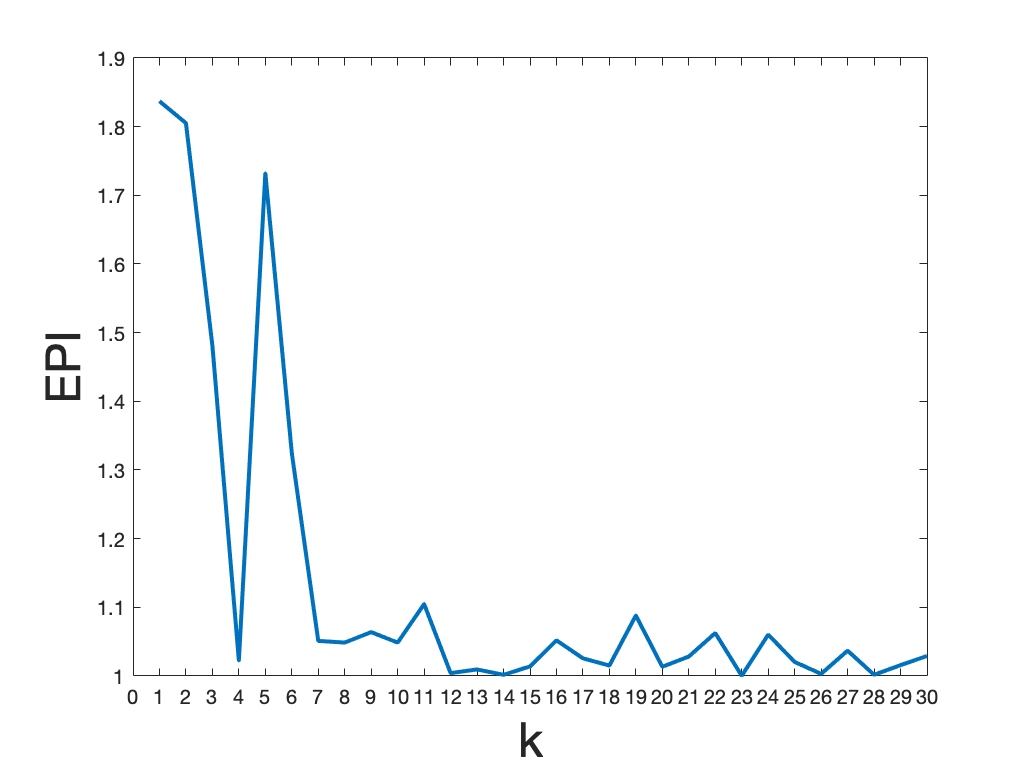

plot(out.ratio(1:30),'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);
xticks(0:30);

## MuTrans Dynamical Analysis of the Single-Cell Data

parameter and option settings

rng(1)
par.perplex = 150;
par.K_cluster = 5;
par.trails = 10;

% Dynamical Analysis and Output
tic;
Output = DynamicalAnalysis (data, par);

Mean value of sigma: 0.31647
Minimum value of sigma: 0.20125
Maximum value of sigma: 0.47305
Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 37.9856
Iteration 20: error is 37.1596
Iteration 30: error is 36.8526
Iteration 40: error is 36.9056
Iteration 50: error is 37.1134
Iteration 60: error is 37.406
Iteration 70: error is 37.3699
Iteration 80: error is 36.9494
Iteration 90: error is 36.9281
Iteration 100: error is 2.2875
Iteration 110: error is 1.567
Iteration 120: error is 1.0567
Iteration 130: error is 0.89392
Iteration 140: error is 0.83599
Iteration 150: error is 0.80564
Iteration 160: error is 0.78597
Iteration 170: error is 0.75964
Iteration 180: error is 0.74636
Iteration 190: error is 0.73579
Iteration 200: error is 0.73021
Iteration 210: error is 0.72741
Iteration 220: error is 0.72324
Iteration 230: error is 0.71982
Iteration 240: error is 0.70575
Iteration 250: error is 0.69956
Iteration 260: error is 0.708

J_new = 2.2652

J_new = 2.2618

J_new = 2.2612

J_new = 2.2605

J_new = 2.2615

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.1392
Iteration 20: error is 37.2285
Iteration 30: error is 37.4476
Iteration 40: error is 36.9292
Iteration 50: error is 37.8844
Iteration 60: error is 37.5727
Iteration 70: error is 37.293
Iteration 80: error is 37.0892
Iteration 90: error is 37.0873
Iteration 100: error is 2.4737
Iteration 110: error is 1.3335
Iteration 120: error is 0.94553
Iteration 130: error is 0.82238
Iteration 140: error is 0.78584
Iteration 150: error is 0.76528
Iteration 160: error is 0.74738
Iteration 170: error is 0.72639
Iteration 180: error is 0.71826
Iteration 190: error is 0.71168
Iteration 200: error is 0.70724
Iteration 210: error is 0.70228
Iteration 220: error is 0.69828
Iteration 230: error is 0.69516
Iteration 240: error is 0.69261
Iteration 250: error is 0.68893
Iteration 260: error is 0.68149
Iteration 270: error is 0.67629
Iteration 280: error is 0.67379
Iteration 290: error is 

J_new = 2.2677

J_new = 2.2634

J_new = 2.2633

J_new = 2.2631

J_new = 2.2631

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.9604
Iteration 20: error is 37.3235
Iteration 30: error is 36.3542
Iteration 40: error is 37.1061
Iteration 50: error is 37.5654
Iteration 60: error is 37.5175
Iteration 70: error is 37.1518
Iteration 80: error is 37.4323
Iteration 90: error is 36.9327
Iteration 100: error is 2.4129
Iteration 110: error is 1.2516
Iteration 120: error is 0.86426
Iteration 130: error is 0.79763
Iteration 140: error is 0.76539
Iteration 150: error is 0.74635
Iteration 160: error is 0.73355
Iteration 170: error is 0.71846
Iteration 180: error is 0.7103
Iteration 190: error is 0.70436
Iteration 200: error is 0.69732
Iteration 210: error is 0.69287
Iteration 220: error is 0.68844
Iteration 230: error is 0.68381
Iteration 240: error is 0.68057
Iteration 250: error is 0.67456
Iteration 260: error is 0.67219
Iteration 270: error is 0.66985
Iteration 280: error is 0.66811
Iteration 290: error is 

J_new = 2.2753

J_new = 2.2759

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.8897
Iteration 20: error is 36.8817
Iteration 30: error is 36.7853
Iteration 40: error is 36.6694
Iteration 50: error is 36.6777
Iteration 60: error is 36.7996
Iteration 70: error is 36.8549
Iteration 80: error is 36.8385
Iteration 90: error is 36.4959
Iteration 100: error is 2.3873
Iteration 110: error is 1.1704
Iteration 120: error is 0.8967
Iteration 130: error is 0.79162
Iteration 140: error is 0.75466
Iteration 150: error is 0.72457
Iteration 160: error is 0.70395
Iteration 170: error is 0.69671
Iteration 180: error is 0.69124
Iteration 190: error is 0.68655
Iteration 200: error is 0.68291
Iteration 210: error is 0.68035
Iteration 220: error is 0.67827
Iteration 230: error is 0.67602
Iteration 240: error is 0.67488
Iteration 250: error is 0.67305
Iteration 260: error is 0.67093
Iteration 270: error is 0.66848
Iteration 280: error is 0.66665
Iteration 290: error is 

J_new = 2.2727

J_new = 2.2660

J_new = 2.2660

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.4695
Iteration 20: error is 37.195
Iteration 30: error is 37.2319
Iteration 40: error is 36.9204
Iteration 50: error is 36.9616
Iteration 60: error is 37.295
Iteration 70: error is 36.8216
Iteration 80: error is 36.9454
Iteration 90: error is 36.9095
Iteration 100: error is 2.288
Iteration 110: error is 1.3952
Iteration 120: error is 1.0006
Iteration 130: error is 0.82612
Iteration 140: error is 0.78398
Iteration 150: error is 0.76718
Iteration 160: error is 0.75516
Iteration 170: error is 0.74761
Iteration 180: error is 0.72729
Iteration 190: error is 0.70976
Iteration 200: error is 0.70501
Iteration 210: error is 0.70096
Iteration 220: error is 0.69811
Iteration 230: error is 0.69571
Iteration 240: error is 0.6936
Iteration 250: error is 0.68911
Iteration 260: error is 0.68553
Iteration 270: error is 0.68253
Iteration 280: error is 0.67954
Iteration 290: error is 0.66

J_new = 2.2752

J_new = 2.2703

J_new = 2.2695

J_new = 2.2696

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.1064
Iteration 20: error is 37.3409
Iteration 30: error is 37.2861
Iteration 40: error is 36.5248
Iteration 50: error is 36.9694
Iteration 60: error is 37.4923
Iteration 70: error is 36.9376
Iteration 80: error is 37.2069
Iteration 90: error is 36.512
Iteration 100: error is 2.2372
Iteration 110: error is 1.538
Iteration 120: error is 1.0535
Iteration 130: error is 0.91529
Iteration 140: error is 0.86759
Iteration 150: error is 0.78624
Iteration 160: error is 0.75976
Iteration 170: error is 0.73999
Iteration 180: error is 0.70932
Iteration 190: error is 0.6882
Iteration 200: error is 0.67767
Iteration 210: error is 0.67363
Iteration 220: error is 0.67114
Iteration 230: error is 0.66941
Iteration 240: error is 0.66736
Iteration 250: error is 0.66601
Iteration 260: error is 0.66388
Iteration 270: error is 0.66145
Iteration 280: error is 0.65967
Iteration 290: error is 0.6

J_new = 2.2725

J_new = 2.2679

J_new = 2.2687

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.5527
Iteration 20: error is 36.8034
Iteration 30: error is 36.6869
Iteration 40: error is 37.2689
Iteration 50: error is 37.569
Iteration 60: error is 37.5004
Iteration 70: error is 36.9259
Iteration 80: error is 37.0612
Iteration 90: error is 36.9307
Iteration 100: error is 2.3025
Iteration 110: error is 1.4229
Iteration 120: error is 0.99889
Iteration 130: error is 0.86967
Iteration 140: error is 0.79621
Iteration 150: error is 0.7432
Iteration 160: error is 0.72344
Iteration 170: error is 0.71306
Iteration 180: error is 0.70569
Iteration 190: error is 0.69994
Iteration 200: error is 0.69642
Iteration 210: error is 0.69271
Iteration 220: error is 0.68907
Iteration 230: error is 0.68639
Iteration 240: error is 0.68161
Iteration 250: error is 0.67957
Iteration 260: error is 0.67565
Iteration 270: error is 0.6724
Iteration 280: error is 0.66878
Iteration 290: error is 0.

J_new = 2.2788

J_new = 2.2661

J_new = 2.2628

J_new = 2.2598

J_new = 2.2585

J_new = 2.2585

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.7327
Iteration 20: error is 37.1775
Iteration 30: error is 36.7513
Iteration 40: error is 37.2733
Iteration 50: error is 36.9821
Iteration 60: error is 37.5302
Iteration 70: error is 37.0496
Iteration 80: error is 37.0732
Iteration 90: error is 37.5623
Iteration 100: error is 2.4839
Iteration 110: error is 1.5122
Iteration 120: error is 1.0889
Iteration 130: error is 0.91029
Iteration 140: error is 0.80005
Iteration 150: error is 0.75757
Iteration 160: error is 0.74235
Iteration 170: error is 0.73517
Iteration 180: error is 0.73216
Iteration 190: error is 0.72659
Iteration 200: error is 0.72419
Iteration 210: error is 0.72128
Iteration 220: error is 0.71971
Iteration 230: error is 0.71731
Iteration 240: error is 0.7158
Iteration 250: error is 0.71411
Iteration 260: error is 0.71219
Iteration 270: error is 0.70985
Iteration 280: error is 0.7082
Iteration 290: error is 0.

J_new = 2.2652

J_new = 2.2641

J_new = 2.2597

J_new = 2.2623

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.9646
Iteration 20: error is 37.4715
Iteration 30: error is 36.8269
Iteration 40: error is 36.8668
Iteration 50: error is 37.1911
Iteration 60: error is 37.0922
Iteration 70: error is 37.0382
Iteration 80: error is 37.0184
Iteration 90: error is 37.2661
Iteration 100: error is 2.3657
Iteration 110: error is 1.3677
Iteration 120: error is 0.90739
Iteration 130: error is 0.80807
Iteration 140: error is 0.76209
Iteration 150: error is 0.73698
Iteration 160: error is 0.72
Iteration 170: error is 0.71172
Iteration 180: error is 0.7064
Iteration 190: error is 0.69733
Iteration 200: error is 0.69364
Iteration 210: error is 0.68996
Iteration 220: error is 0.68733
Iteration 230: error is 0.68531
Iteration 240: error is 0.68365
Iteration 250: error is 0.68288
Iteration 260: error is 0.68047
Iteration 270: error is 0.67787
Iteration 280: error is 0.67622
Iteration 290: error is 0.6

J_new = 2.2542

J_new = 2.2594

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 39.0757
Iteration 20: error is 37.9297
Iteration 30: error is 37.5633
Iteration 40: error is 36.7777
Iteration 50: error is 37.2106
Iteration 60: error is 37.4442
Iteration 70: error is 37.2684
Iteration 80: error is 37.3826
Iteration 90: error is 37.4374
Iteration 100: error is 2.6328
Iteration 110: error is 1.3927
Iteration 120: error is 1.0415
Iteration 130: error is 0.86193
Iteration 140: error is 0.81184
Iteration 150: error is 0.76133
Iteration 160: error is 0.74929
Iteration 170: error is 0.74278
Iteration 180: error is 0.73739
Iteration 190: error is 0.72899
Iteration 200: error is 0.72388
Iteration 210: error is 0.72124
Iteration 220: error is 0.71876
Iteration 230: error is 0.71666
Iteration 240: error is 0.71514
Iteration 250: error is 0.71375
Iteration 260: error is 0.71181
Iteration 270: error is 0.70934
Iteration 280: error is 0.70754
Iteration 290: error is 

J_new = 2.2691

J_new = 2.2640

J_new = 2.2601

J_new = 2.2568

J_new = 2.2550

J_new = 2.2550

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.2464
Iteration 20: error is 37.1683
Iteration 30: error is 37.313
Iteration 40: error is 36.9243
Iteration 50: error is 37.3881
Iteration 60: error is 36.906
Iteration 70: error is 36.9932
Iteration 80: error is 36.8448
Iteration 90: error is 37.2799
Iteration 100: error is 2.3523
Iteration 110: error is 1.4488
Iteration 120: error is 0.96342
Iteration 130: error is 0.83792
Iteration 140: error is 0.78305
Iteration 150: error is 0.75688
Iteration 160: error is 0.74273
Iteration 170: error is 0.73162
Iteration 180: error is 0.72592
Iteration 190: error is 0.72093
Iteration 200: error is 0.71685
Iteration 210: error is 0.7137
Iteration 220: error is 0.71152
Iteration 230: error is 0.70911
Iteration 240: error is 0.70738
Iteration 250: error is 0.7061
Iteration 260: error is 0.70386
Iteration 270: error is 0.70144
Iteration 280: error is 0.6996
Iteration 290: error is 0.69

J_new = 2.2691

J_new = 2.2628

J_new = 2.2636

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.9519
Iteration 20: error is 37.2142
Iteration 30: error is 36.6059
Iteration 40: error is 37.6004
Iteration 50: error is 37.2871
Iteration 60: error is 36.9064
Iteration 70: error is 37.0121
Iteration 80: error is 37.4754
Iteration 90: error is 37.3633
Iteration 100: error is 2.488
Iteration 110: error is 1.4853
Iteration 120: error is 1.0247
Iteration 130: error is 0.87301
Iteration 140: error is 0.77322
Iteration 150: error is 0.73979
Iteration 160: error is 0.725
Iteration 170: error is 0.71782
Iteration 180: error is 0.71236
Iteration 190: error is 0.70786
Iteration 200: error is 0.70436
Iteration 210: error is 0.70163
Iteration 220: error is 0.6997
Iteration 230: error is 0.69713
Iteration 240: error is 0.69537
Iteration 250: error is 0.694
Iteration 260: error is 0.69171
Iteration 270: error is 0.68939
Iteration 280: error is 0.68745
Iteration 290: error is 0.6861

J_new = 2.2537

J_new = 2.2472

J_new = 2.2375

J_new = 2.2357

J_new = 2.2358

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.7446
Iteration 20: error is 36.8274
Iteration 30: error is 37.5568
Iteration 40: error is 37.1183
Iteration 50: error is 36.8699
Iteration 60: error is 36.7323
Iteration 70: error is 36.9032
Iteration 80: error is 37.1685
Iteration 90: error is 36.5594
Iteration 100: error is 2.4166
Iteration 110: error is 1.2823
Iteration 120: error is 0.88869
Iteration 130: error is 0.77685
Iteration 140: error is 0.73077
Iteration 150: error is 0.70879
Iteration 160: error is 0.69494
Iteration 170: error is 0.68341
Iteration 180: error is 0.67495
Iteration 190: error is 0.66844
Iteration 200: error is 0.66434
Iteration 210: error is 0.6615
Iteration 220: error is 0.65893
Iteration 230: error is 0.65674
Iteration 240: error is 0.65474
Iteration 250: error is 0.65364
Iteration 260: error is 0.6507
Iteration 270: error is 0.64814
Iteration 280: error is 0.64637
Iteration 290: error is 0

J_new = 2.2754

J_new = 2.2702

J_new = 2.2655

J_new = 2.2598

J_new = 2.2605

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.2643
Iteration 20: error is 36.9685
Iteration 30: error is 36.94
Iteration 40: error is 37.2156
Iteration 50: error is 37.5413
Iteration 60: error is 37.2994
Iteration 70: error is 37.188
Iteration 80: error is 37.3317
Iteration 90: error is 37.6978
Iteration 100: error is 2.2895
Iteration 110: error is 1.5146
Iteration 120: error is 1.0245
Iteration 130: error is 0.84753
Iteration 140: error is 0.78473
Iteration 150: error is 0.72154
Iteration 160: error is 0.70517
Iteration 170: error is 0.69533
Iteration 180: error is 0.68982
Iteration 190: error is 0.68369
Iteration 200: error is 0.67765
Iteration 210: error is 0.66788
Iteration 220: error is 0.66507
Iteration 230: error is 0.66305
Iteration 240: error is 0.66174
Iteration 250: error is 0.66013
Iteration 260: error is 0.65778
Iteration 270: error is 0.6552
Iteration 280: error is 0.65317
Iteration 290: error is 0.65

J_new = 2.2682

J_new = 2.2655

J_new = 2.2634

J_new = 2.2651

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.7909
Iteration 20: error is 37.2594
Iteration 30: error is 36.564
Iteration 40: error is 36.7916
Iteration 50: error is 37.7159
Iteration 60: error is 37.114
Iteration 70: error is 37.367
Iteration 80: error is 37.3783
Iteration 90: error is 37.2317
Iteration 100: error is 2.4098
Iteration 110: error is 1.3131
Iteration 120: error is 0.9695
Iteration 130: error is 0.84838
Iteration 140: error is 0.77847
Iteration 150: error is 0.75989
Iteration 160: error is 0.74234
Iteration 170: error is 0.72332
Iteration 180: error is 0.71589
Iteration 190: error is 0.71037
Iteration 200: error is 0.70728
Iteration 210: error is 0.70343
Iteration 220: error is 0.70155
Iteration 230: error is 0.69906
Iteration 240: error is 0.69839
Iteration 250: error is 0.69624
Iteration 260: error is 0.6931
Iteration 270: error is 0.69003
Iteration 280: error is 0.68862
Iteration 290: error is 0.68

J_new = 2.2826

J_new = 2.2744

J_new = 2.2713

J_new = 2.2700

J_new = 2.2667

J_new = 2.2667

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.5184
Iteration 20: error is 37.2731
Iteration 30: error is 37.4649
Iteration 40: error is 37.9811
Iteration 50: error is 37.139
Iteration 60: error is 37.3529
Iteration 70: error is 37.2777
Iteration 80: error is 37.5352
Iteration 90: error is 37.3431
Iteration 100: error is 2.4755
Iteration 110: error is 1.4146
Iteration 120: error is 0.9925
Iteration 130: error is 0.88643
Iteration 140: error is 0.82629
Iteration 150: error is 0.7944
Iteration 160: error is 0.76788
Iteration 170: error is 0.76171
Iteration 180: error is 0.75321
Iteration 190: error is 0.74795
Iteration 200: error is 0.7438
Iteration 210: error is 0.74111
Iteration 220: error is 0.73779
Iteration 230: error is 0.73421
Iteration 240: error is 0.7166
Iteration 250: error is 0.71717
Iteration 260: error is 0.71476
Iteration 270: error is 0.70305
Iteration 280: error is 0.70016
Iteration 290: error is 0.69

J_new = 2.2788

J_new = 2.2741

J_new = 2.2713

J_new = 2.2700

J_new = 2.2690

J_new = 2.2690

J_new = 2.2690

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 38.5502
Iteration 20: error is 37.4041
Iteration 30: error is 36.7812
Iteration 40: error is 36.8421
Iteration 50: error is 37.0557
Iteration 60: error is 36.8589
Iteration 70: error is 37.217
Iteration 80: error is 37.0804
Iteration 90: error is 36.4891
Iteration 100: error is 2.4053
Iteration 110: error is 1.3461
Iteration 120: error is 0.97212
Iteration 130: error is 0.87416
Iteration 140: error is 0.79663
Iteration 150: error is 0.76038
Iteration 160: error is 0.74468
Iteration 170: error is 0.73508
Iteration 180: error is 0.72919
Iteration 190: error is 0.7236
Iteration 200: error is 0.71896
Iteration 210: error is 0.7162
Iteration 220: error is 0.71464
Iteration 230: error is 0.71223
Iteration 240: error is 0.71045
Iteration 250: error is 0.70908
Iteration 260: error is 0.70692
Iteration 270: error is 0.70461
Iteration 280: error is 0.70296
Iteration 290: error is 0.

J_new = 2.2775

J_new = 2.2738

J_new = 2.2721

J_new = 2.2722

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 39.1972
Iteration 20: error is 37.4132
Iteration 30: error is 37.3815
Iteration 40: error is 37.1445
Iteration 50: error is 37.1248
Iteration 60: error is 37.2032
Iteration 70: error is 37.1678
Iteration 80: error is 37.7414
Iteration 90: error is 37.4027
Iteration 100: error is 2.4014
Iteration 110: error is 1.3371
Iteration 120: error is 0.96437
Iteration 130: error is 0.90024
Iteration 140: error is 0.84203
Iteration 150: error is 0.79969
Iteration 160: error is 0.77089
Iteration 170: error is 0.74463
Iteration 180: error is 0.73665
Iteration 190: error is 0.72083
Iteration 200: error is 0.68629
Iteration 210: error is 0.68167
Iteration 220: error is 0.67843
Iteration 230: error is 0.67427
Iteration 240: error is 0.67132
Iteration 250: error is 0.67216
Iteration 260: error is 0.66704
Iteration 270: error is 0.66451
Iteration 280: error is 0.66278
Iteration 290: error is

J_new = 2.2769

J_new = 2.2681

J_new = 2.2650

J_new = 2.2642

J_new = 2.2652

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 39.2745
Iteration 20: error is 36.8069
Iteration 30: error is 36.7256
Iteration 40: error is 37.5357
Iteration 50: error is 37.5825
Iteration 60: error is 37.0927
Iteration 70: error is 37.1476
Iteration 80: error is 37.1031
Iteration 90: error is 37.0307
Iteration 100: error is 2.3685
Iteration 110: error is 1.2714
Iteration 120: error is 0.96111
Iteration 130: error is 0.82482
Iteration 140: error is 0.78893
Iteration 150: error is 0.7651
Iteration 160: error is 0.7498
Iteration 170: error is 0.72891
Iteration 180: error is 0.71532
Iteration 190: error is 0.71039
Iteration 200: error is 0.70398
Iteration 210: error is 0.7015
Iteration 220: error is 0.69868
Iteration 230: error is 0.69683
Iteration 240: error is 0.69541
Iteration 250: error is 0.69388
Iteration 260: error is 0.69178
Iteration 270: error is 0.68949
Iteration 280: error is 0.6878
Iteration 290: error is 0.6

J_new = 2.2700

J_new = 2.2602

J_new = 2.2588

J_new = 2.2587

J_new = 2.2587

Mean value of sigma: 0.21198
Minimum value of sigma: 0.13519
Maximum value of sigma: 0.3157
Iteration 10: error is 39.3957
Iteration 20: error is 37.8612
Iteration 30: error is 37.6363
Iteration 40: error is 37.1599
Iteration 50: error is 37.1248
Iteration 60: error is 36.8996
Iteration 70: error is 37.1313
Iteration 80: error is 36.7814
Iteration 90: error is 37.2933
Iteration 100: error is 2.4974
Iteration 110: error is 1.4771
Iteration 120: error is 1.0566
Iteration 130: error is 0.86446
Iteration 140: error is 0.77602
Iteration 150: error is 0.73167
Iteration 160: error is 0.71952
Iteration 170: error is 0.70675
Iteration 180: error is 0.68604
Iteration 190: error is 0.68154
Iteration 200: error is 0.67939
Iteration 210: error is 0.67604
Iteration 220: error is 0.67403
Iteration 230: error is 0.67237
Iteration 240: error is 0.67102
Iteration 250: error is 0.66969
Iteration 260: error is 0.668
Iteration 270: error is 0.66503
Iteration 280: error is 0.66306
Iteration 290: error is 0.

J_new = 2.2811

J_new = 2.2736

J_new = 2.2705

J_new = 2.2680

J_new = 2.2626

J_new = 2.2631

E_best = 0.5460

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          2.23861                      0.000238
     1           8          2.20188        19394.2        0.00156  
     2          10           2.1968       0.226251        0.00149  
     3          11          2.19028              1        0.00156  
     4          12          2.18114              1        0.00102  
     5          13           2.1786              1        0.00146  
     6          14          2.17204              1       0.000802  
     7          15          2.16709              1        0.00131  
     8          17          2.16277       0.437771       0.000938  
     9          19          2.15879       0.462096       0.000751  
    10          21          2.15734       0.276406       0.000317  
    11          22           2.1565              1        0.00076  
    12          24          2.15437            0.

toc;

Elapsed time is 4.294902 seconds.


## Visualization of Results

rng(1)
class_order = Output.class_order;
H = Output.H;
data_perm = Output.data_perm;

k = par.K_cluster;
colors_class = brewermap(k,'set1');
choice_distance = 'cosine';
Dist = squareform(pdist (data_perm,choice_distance));
ydata = tsne_d(Dist,[],[],40);

Mean value of sigma: 0.22394
Minimum value of sigma: 0.14728
Maximum value of sigma: 0.32601
Iteration 10: error is 38.1807
Iteration 20: error is 36.9513
Iteration 30: error is 36.4953
Iteration 40: error is 36.8992
Iteration 50: error is 37.0704
Iteration 60: error is 36.727
Iteration 70: error is 36.8213
Iteration 80: error is 37.3108
Iteration 90: error is 36.6718
Iteration 100: error is 2.2608
Iteration 110: error is 1.1837
Iteration 120: error is 0.82542
Iteration 130: error is 0.74423
Iteration 140: error is 0.69389
Iteration 150: error is 0.67808
Iteration 160: error is 0.65631
Iteration 170: error is 0.64133
Iteration 180: error is 0.63653
Iteration 190: error is 0.63401
Iteration 200: error is 0.63172
Iteration 210: error is 0.63003
Iteration 220: error is 0.62886
Iteration 230: error is 0.62765
Iteration 240: error is 0.62668
Iteration 250: error is 0.62592
Iteration 260: error is 0.62477
Iteration 270: error is 0.62354
Iteration 280: error is 0.62261
Iteration 290: error is

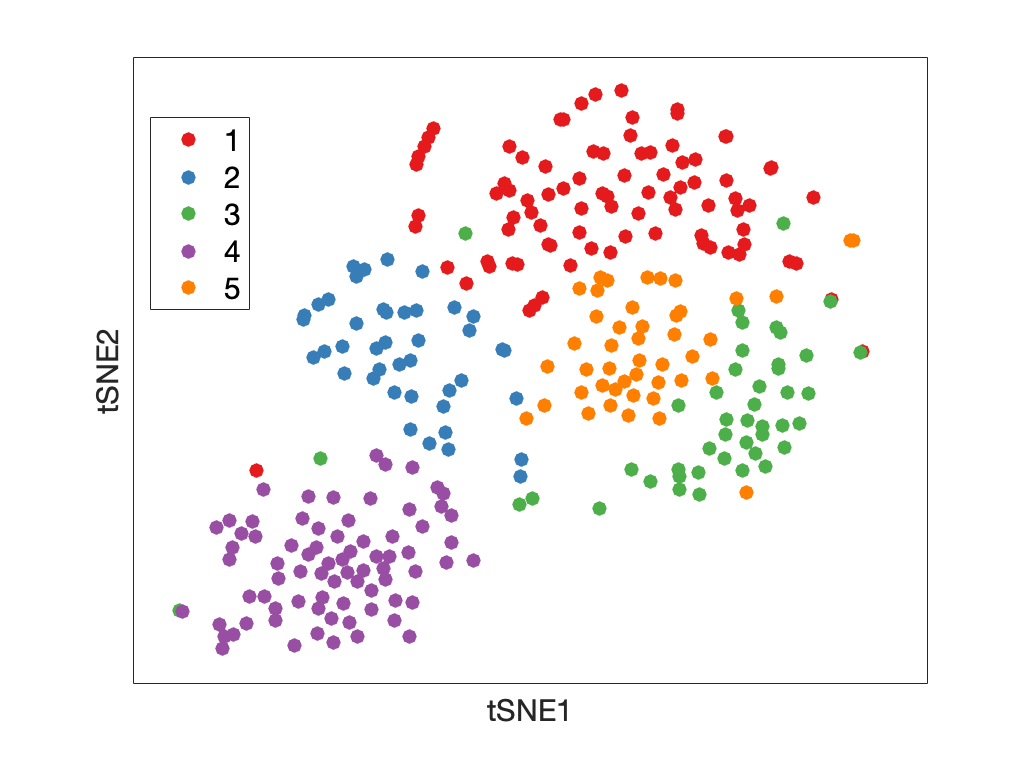

score = ydata;

% MuTrans attrractors
figure;
gscatter(score(:,1),score(:,2),class_order,colors_class,[],25);
set(gca,'xtick',[])
set(gca,'ytick',[])
legend('Fontsize',15)
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

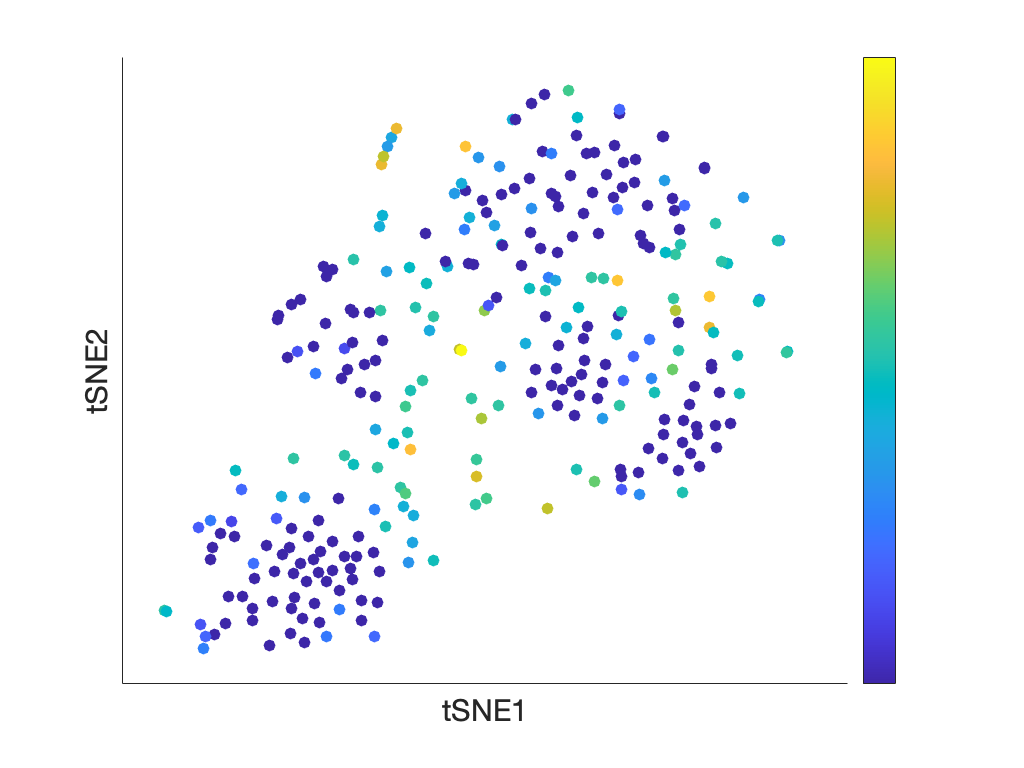


% Entropy of transition cells
figure;
scatter(score(:,1),score(:,2),[],H,'filled');
set(gca,'xtick',[])
set(gca,'ytick',[])
colorbar('Ticks',[]);
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

## **Infer the Cell Lineage (MPFT)**

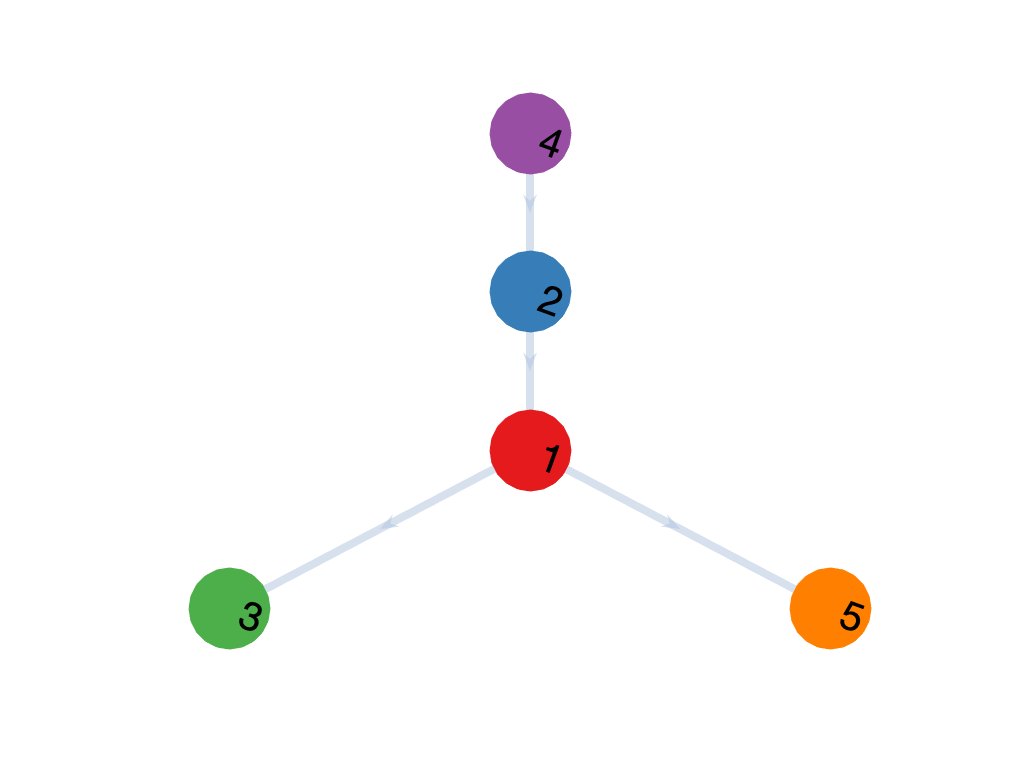

%par.legend_text = {'M','Low-Expression','E'}; %can also specify root by specifying par.root
par.root = 4;
InferLineage(Output, par)

To infer the MPPT (transition trajectory), we recommend to use the python package in the new version of MuTrans.

## Cell-fate Landscape Visualization

2d Projection

P_perm = Output.P_perm;
P_rho = Output.P_rho;

w = 0.5;
P_w = w*P_perm+(1-w)*P_rho;
par.dims = 5;
par.isomap_kn = 50;
score_2d = SC_forced2d (P_w,par);

Constructing neighborhood graph...
Computing shortest paths...
Constructing low-dimensional embedding...


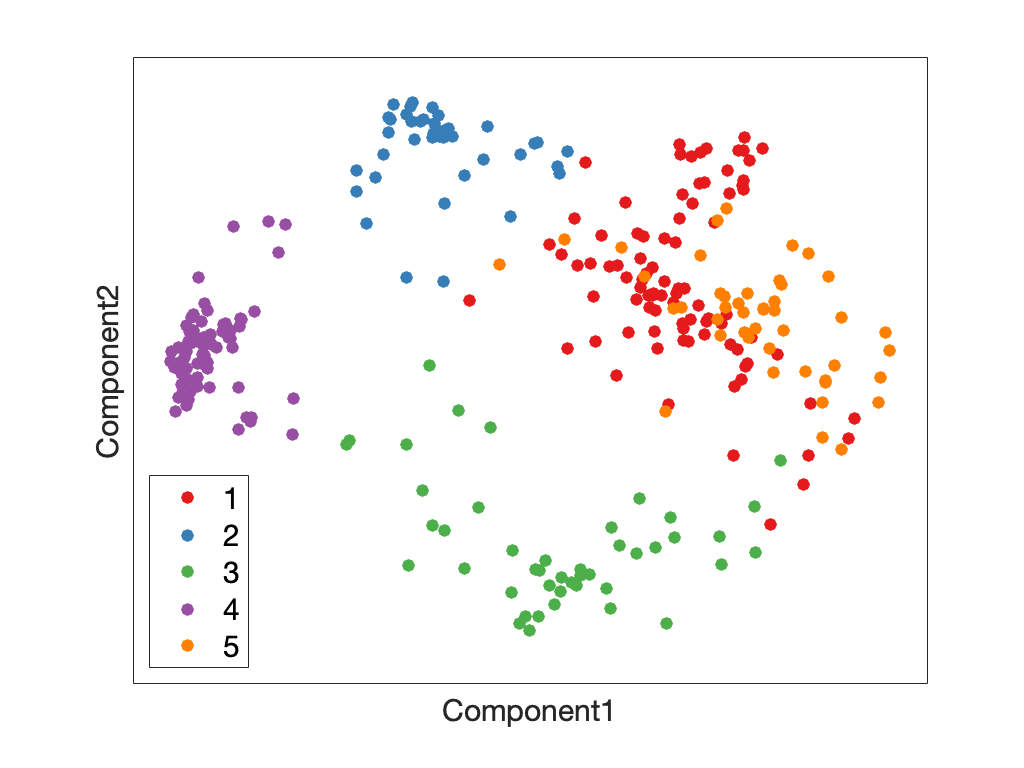


figure;
class_order = Output.class_order;
gscatter(score_2d(:,1),score_2d(:,2),class_order,colors_class,[],22);
legend('Fontsize',15,'Location','SouthWest')
set(gca,'xtick',[],'ytick',[]);
xlabel('Component1','Fontsize',15)
ylabel('Component2','Fontsize',15)



Output.embedding_2d = score_2d;

Landscape Construction

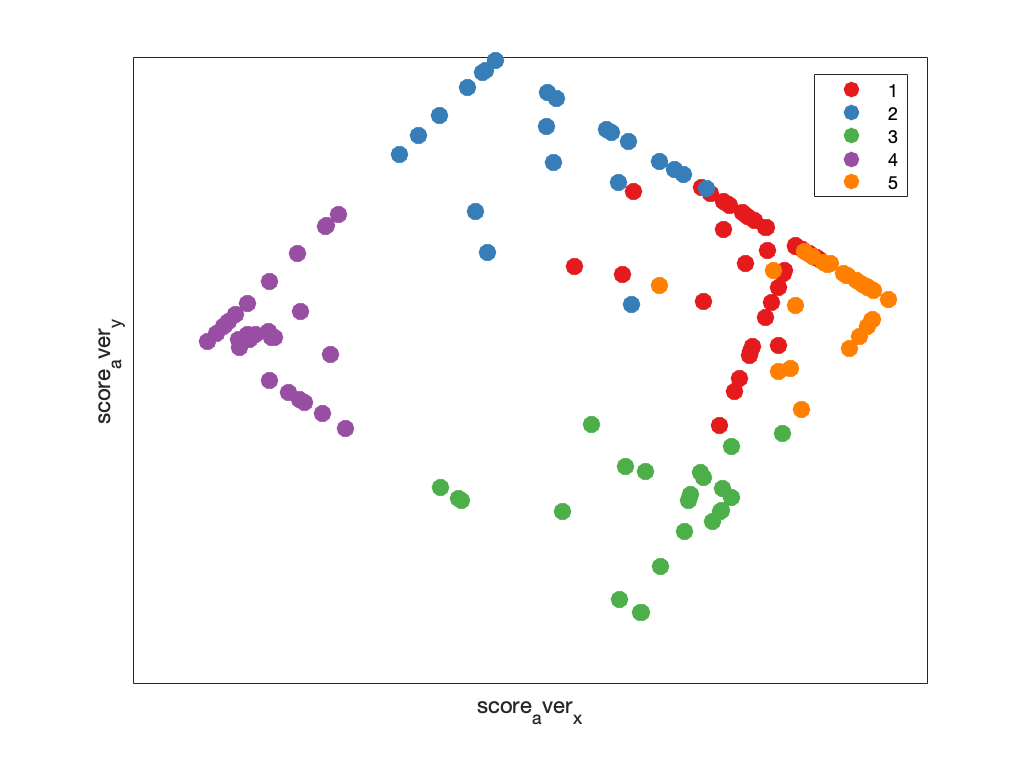

par.legend_text = {'M','Low-Expression','E'};
par.colors = colors_class ;
par.mksize = 30;
land = ConstructLandscape (Output, par);

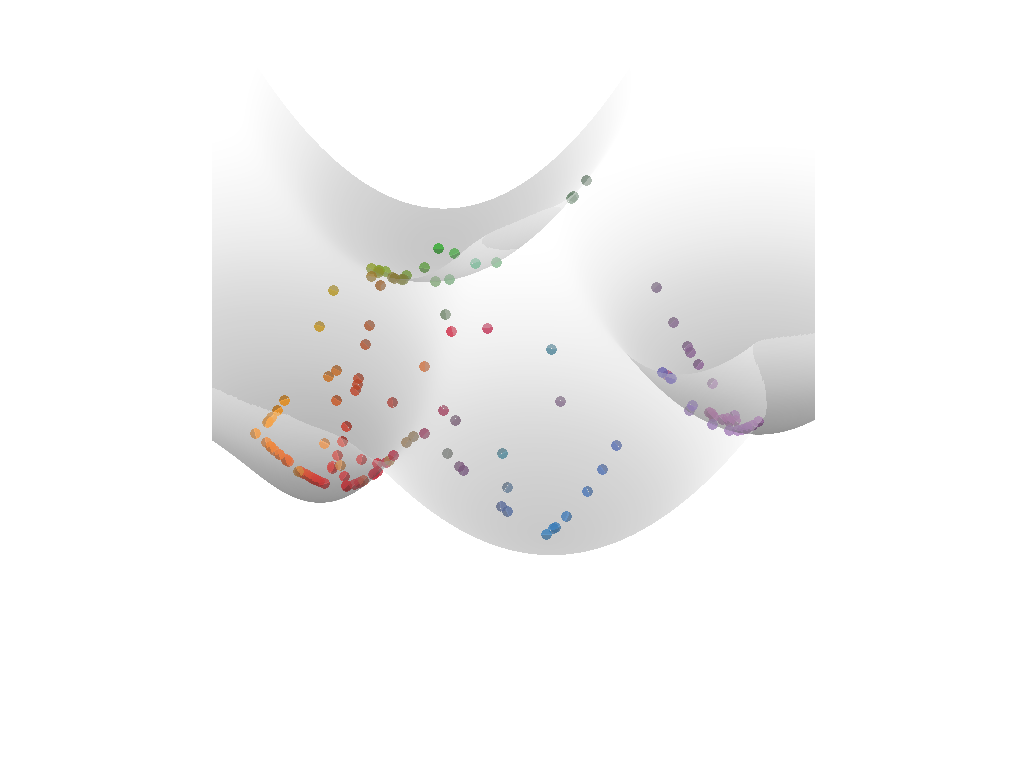

view([180 60])

## Transition Gene Analysis

labs_perm = Output.labs_perm;
par.display_genes_label = true;
par.display_mixing_id = false;
par.genes = genes;
par.thresh_de_pvalues = 5e-4;
par.thresh_ms_pvalues = 1e-4;
par.flip = false;

Direct transition from E to M

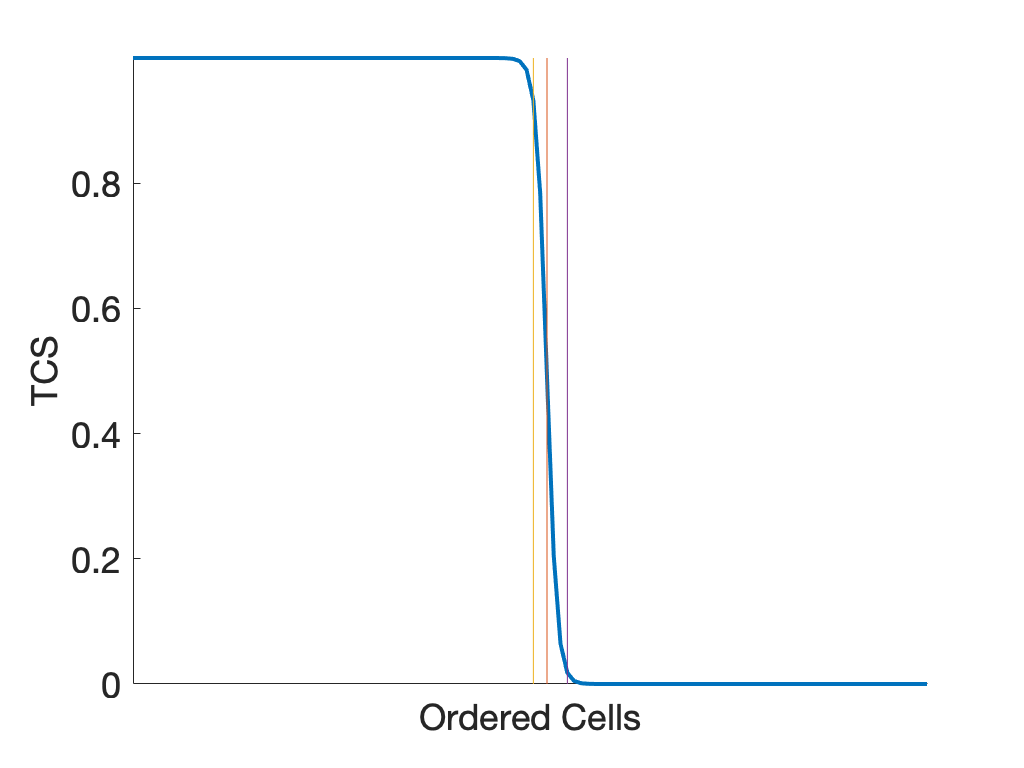

Below is the heatmap of transition genes


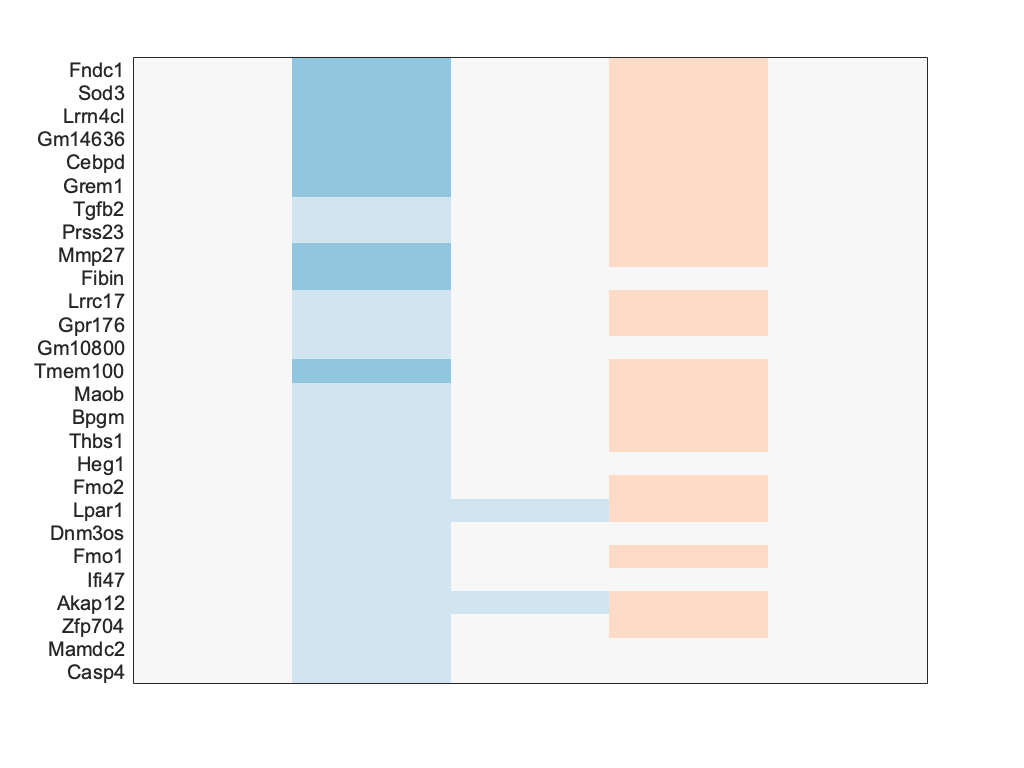

Below is the heatmap of down-regulated MS/IH genes


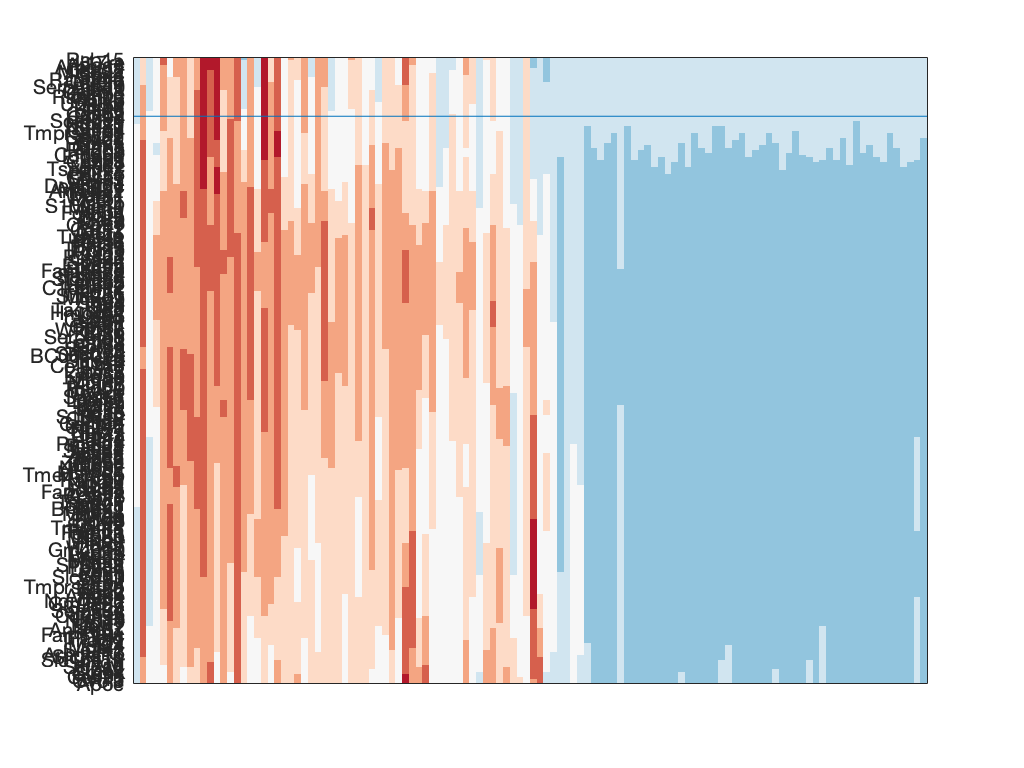

Below is the heatmap of up-regulated MS/IH genes


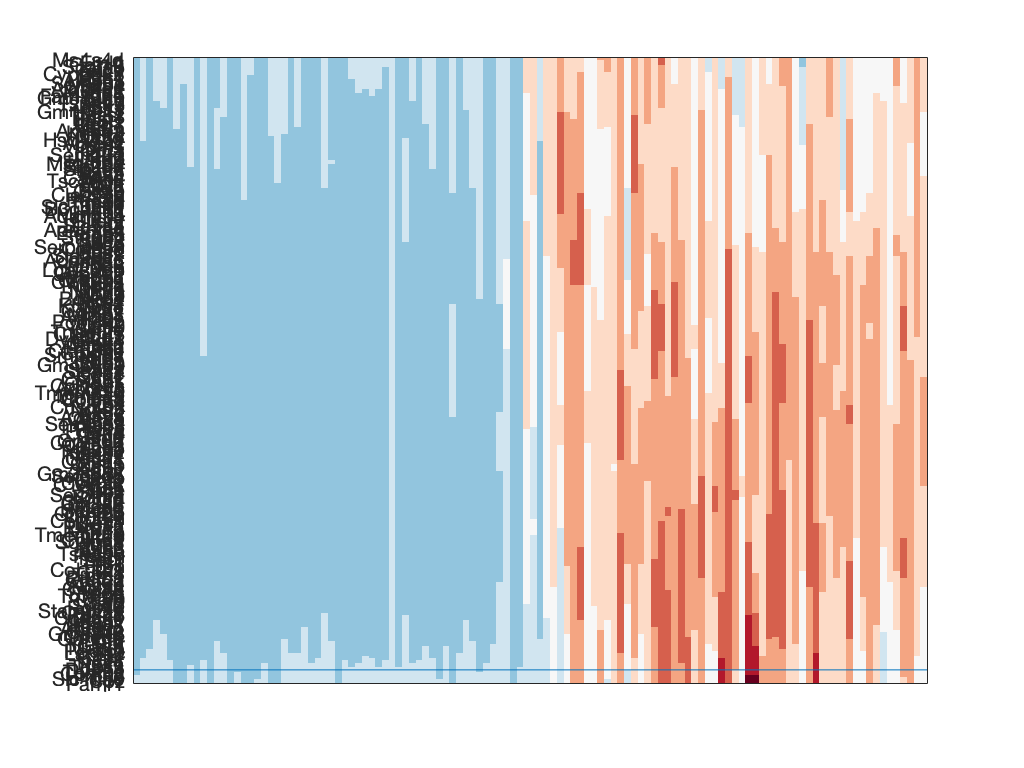

Below is the heatmap of all top genes


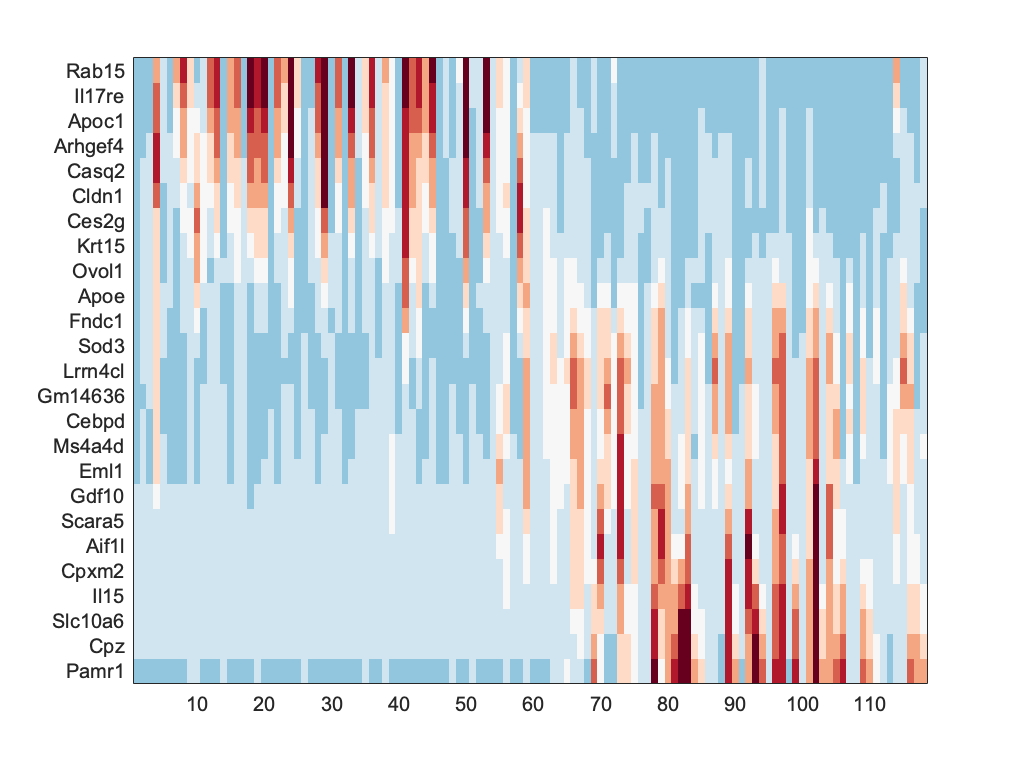

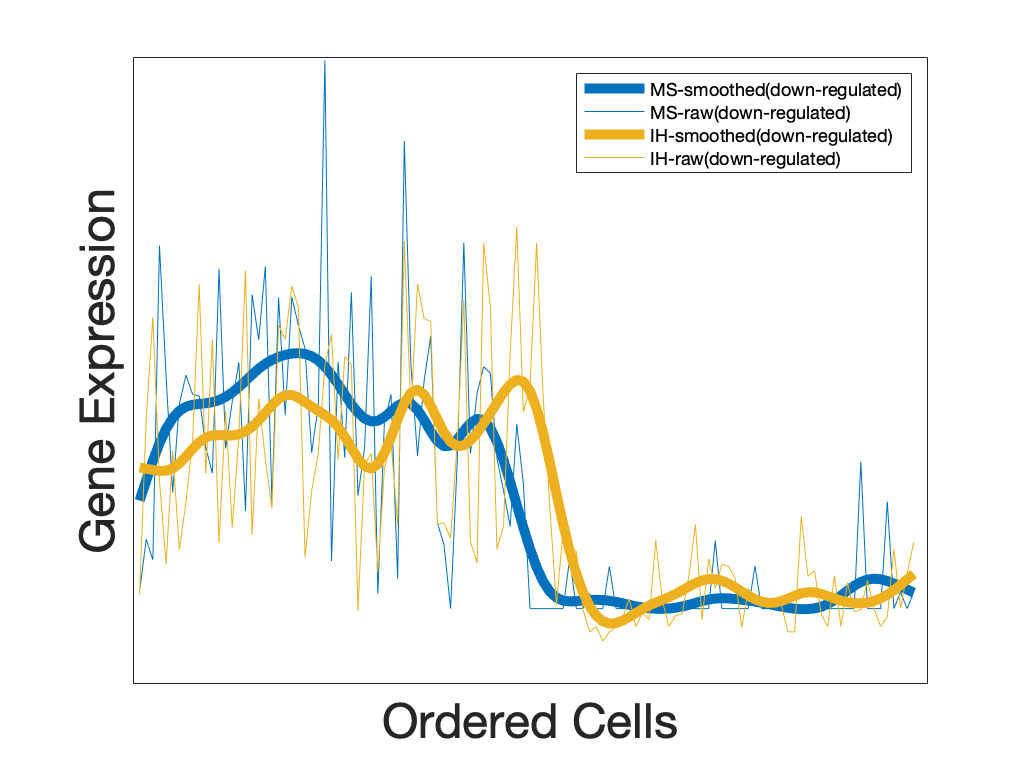

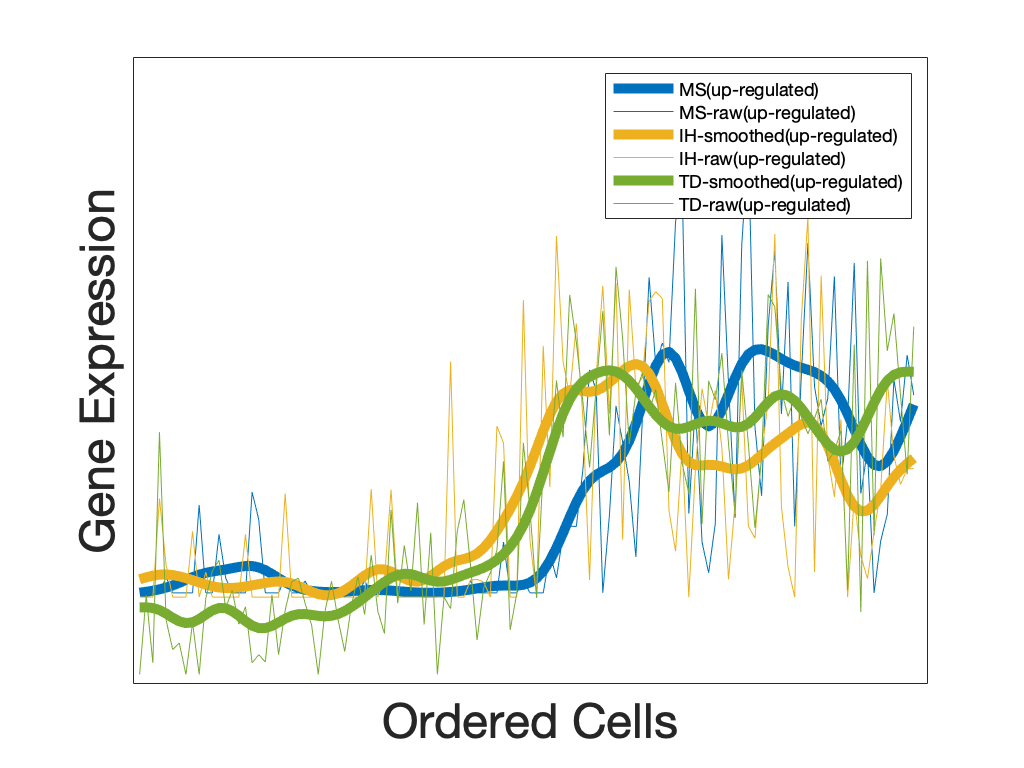

genes_analysis_out_direct = GeneAnalysis(4,1 , Output,par);

Find the list of MS genes in E state

disp(genes_analysis_out_direct.genes_ms_g1)

  Columns 1 through 9

    {'Rab15'}    {'Il17re'}    {'Apoc1'}    {'Arhgef4'}    {'Casq2'}    {'Mfsd2a'}    {'Gpx2'}    {'Sorl1'}    {'Rapgef5'}

  Columns 10 through 18

    {'Cdc20'}    {'Ehf'}    {'Serpinb10'}    {'Plbd1'}    {'Calml3'}    {'Cenpe'}    {'Rassf10'}    {'Trpv3'}    {'Pinlyp'}

  Columns 19 through 24

    {'Upk3bl'}    {'Gjb4'}    {'Klk10'}    {'Flrt1'}    {'Cenpa'}    {'Pole2'}



 transition from E to ICS

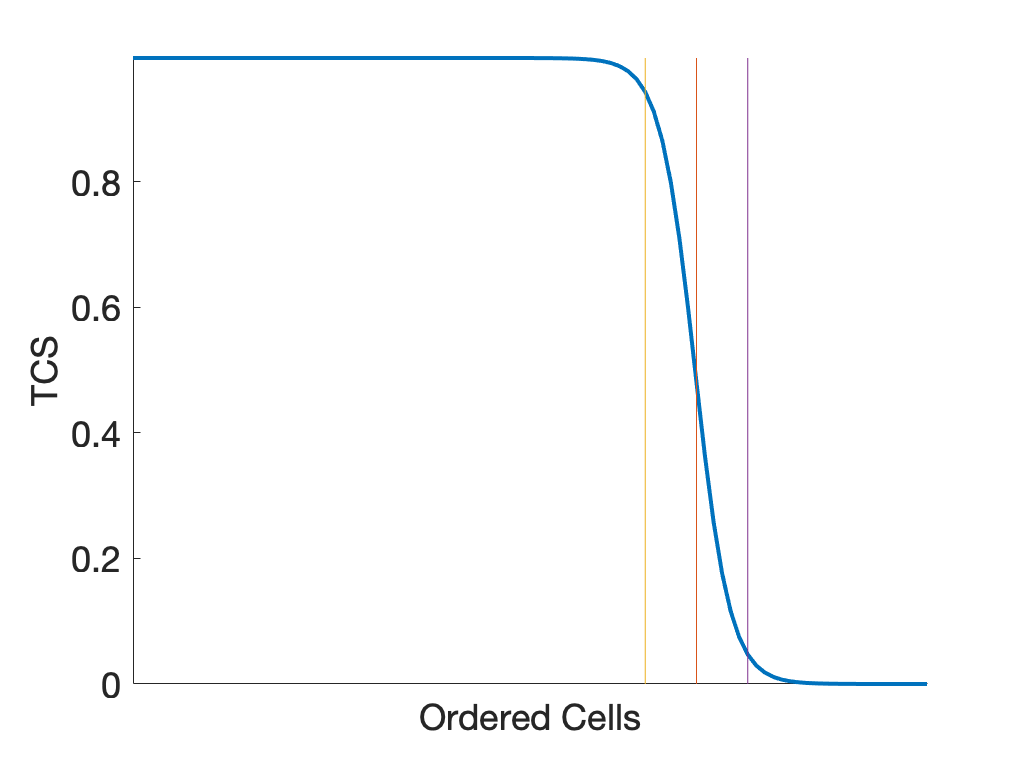

Below is the heatmap of transition genes


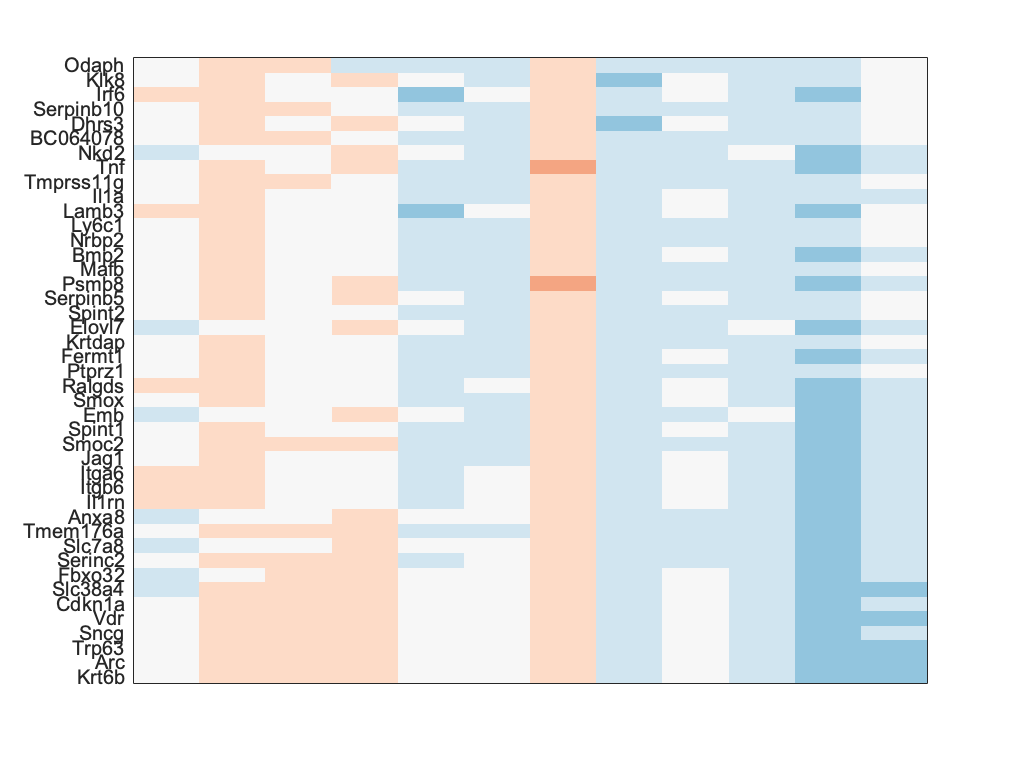

Below is the heatmap of down-regulated MS/IH genes


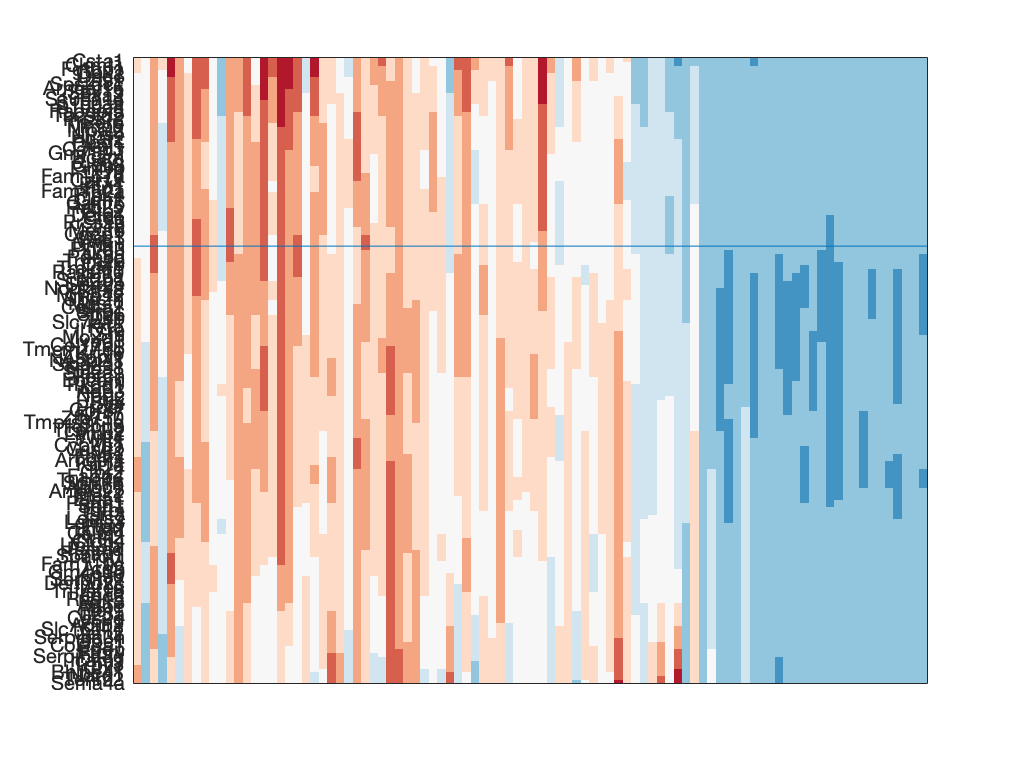

Below is the heatmap of up-regulated MS/IH genes


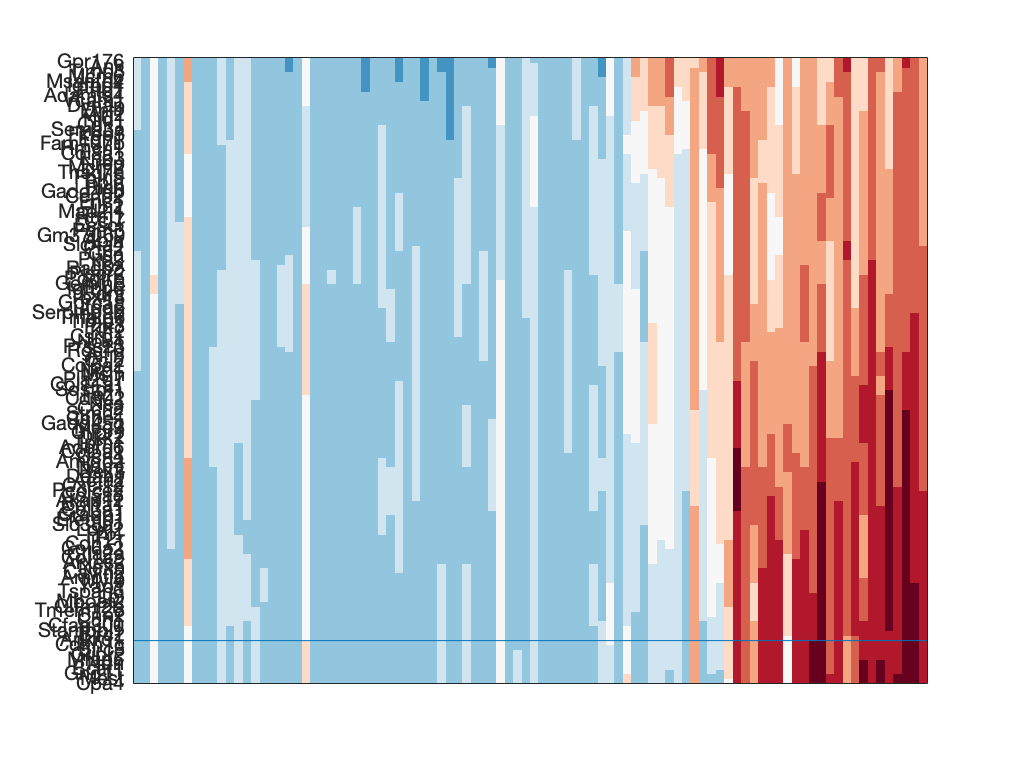

Below is the heatmap of all top genes


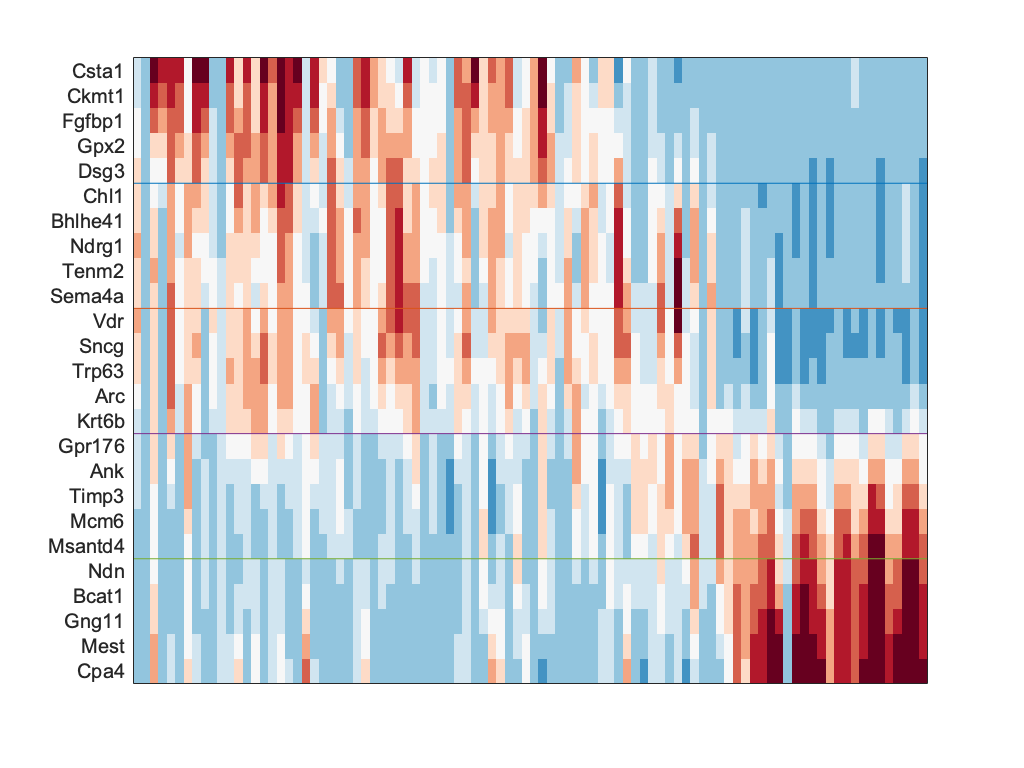

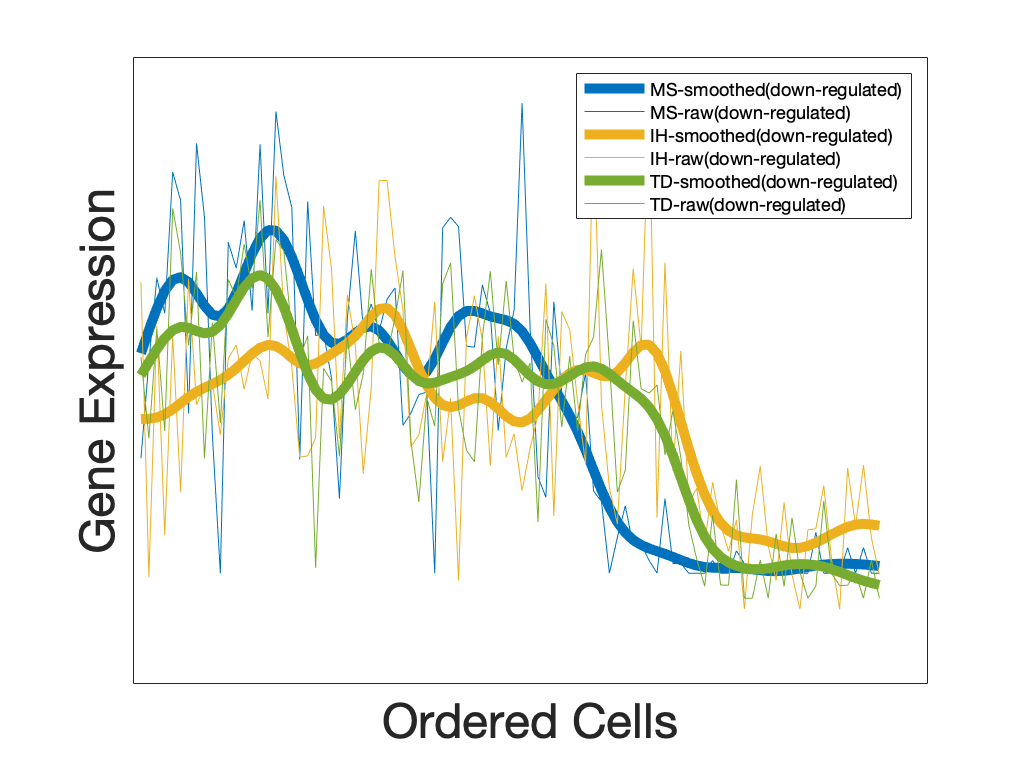

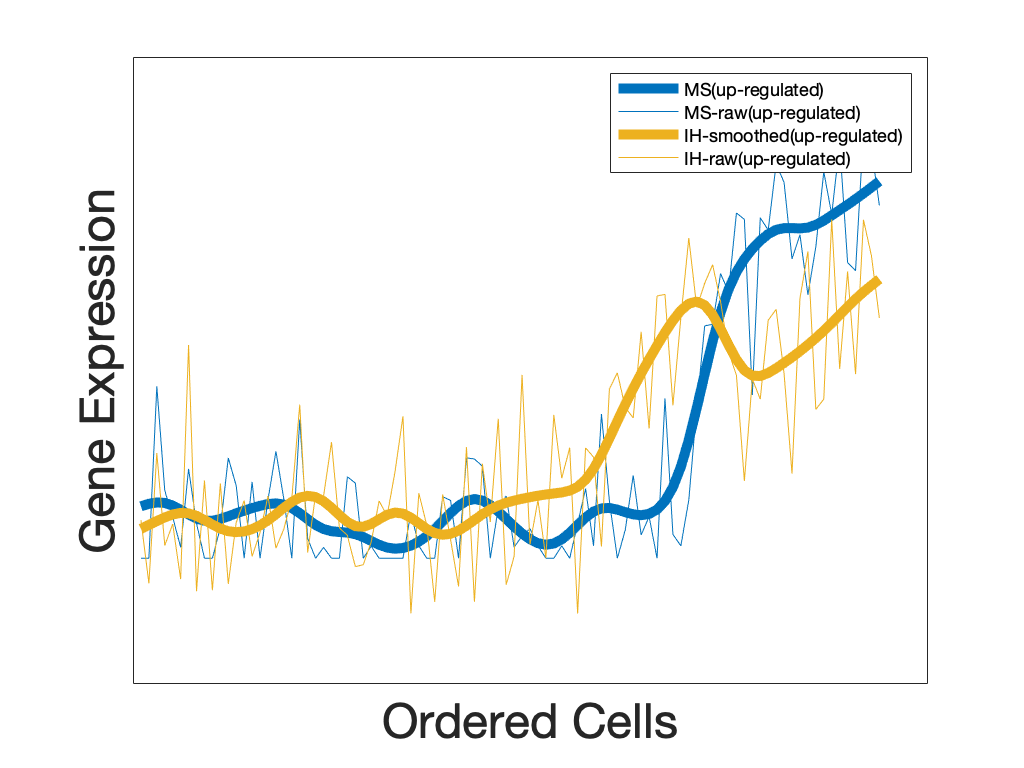

genes_analysis_out_indirect_1 = GeneAnalysis(4, 3, Output,par);

 transition from LE to M

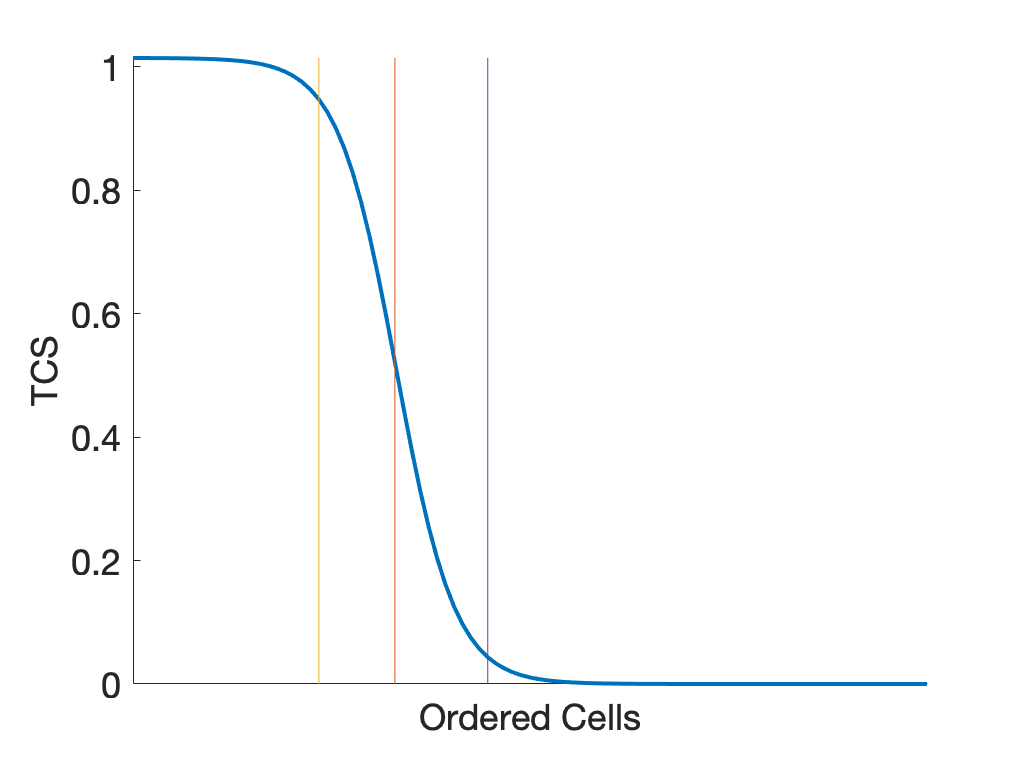

Below is the heatmap of transition genes


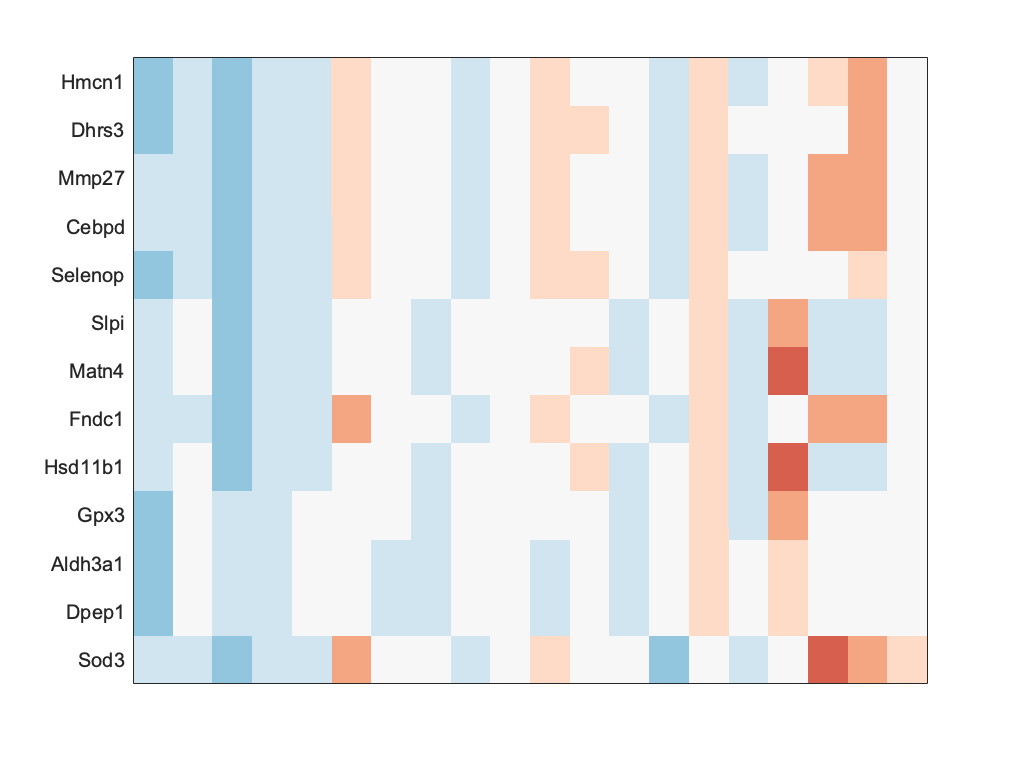

Below is the heatmap of down-regulated MS/IH genes


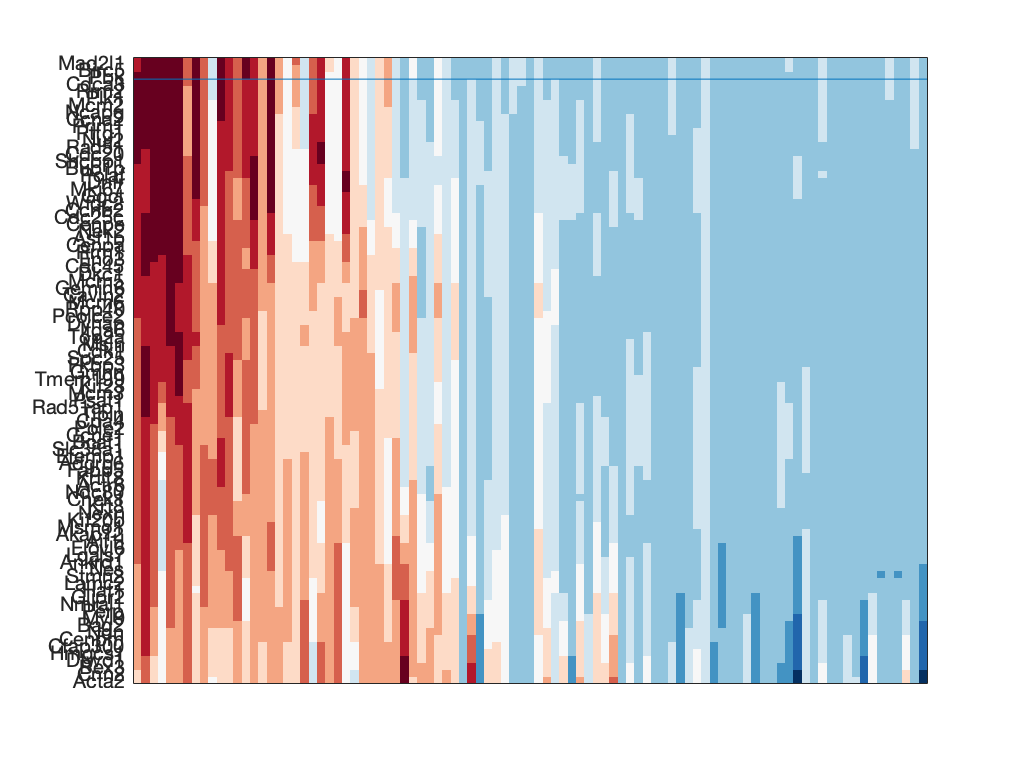

Below is the heatmap of up-regulated MS/IH genes


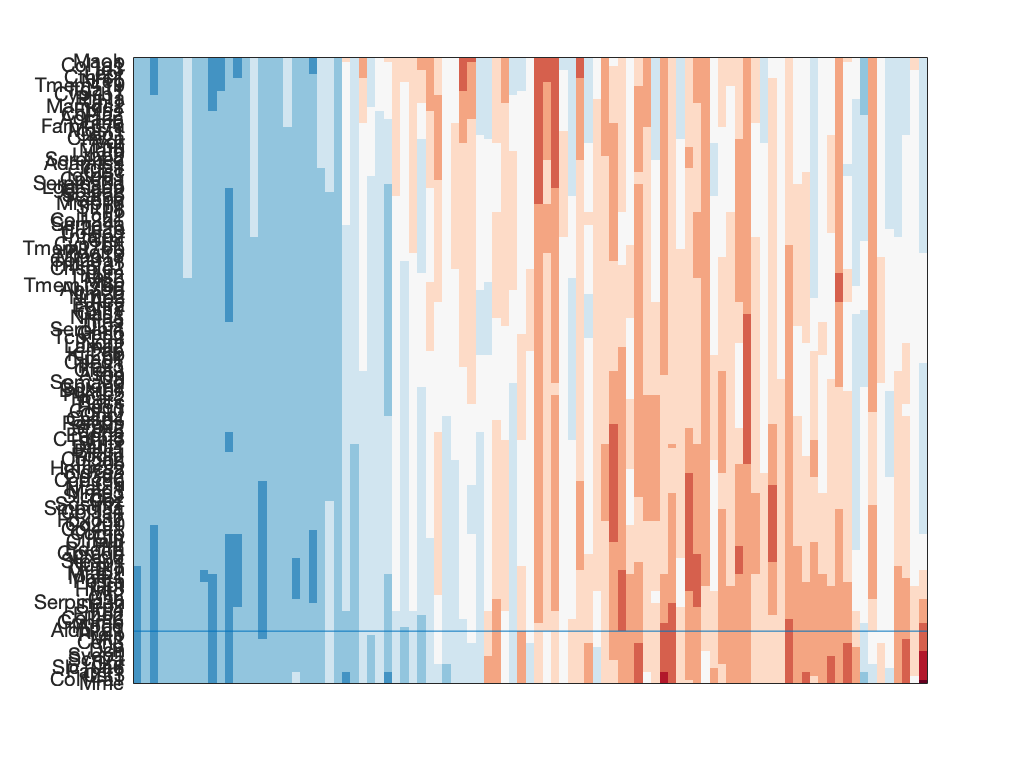

Below is the heatmap of all top genes


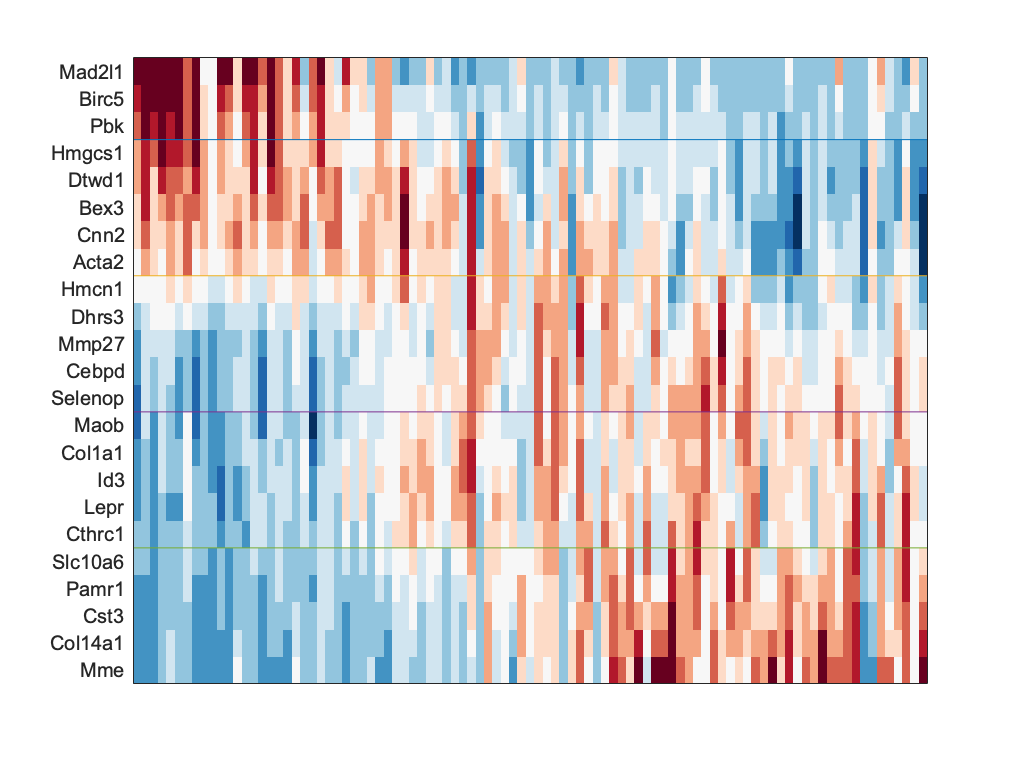

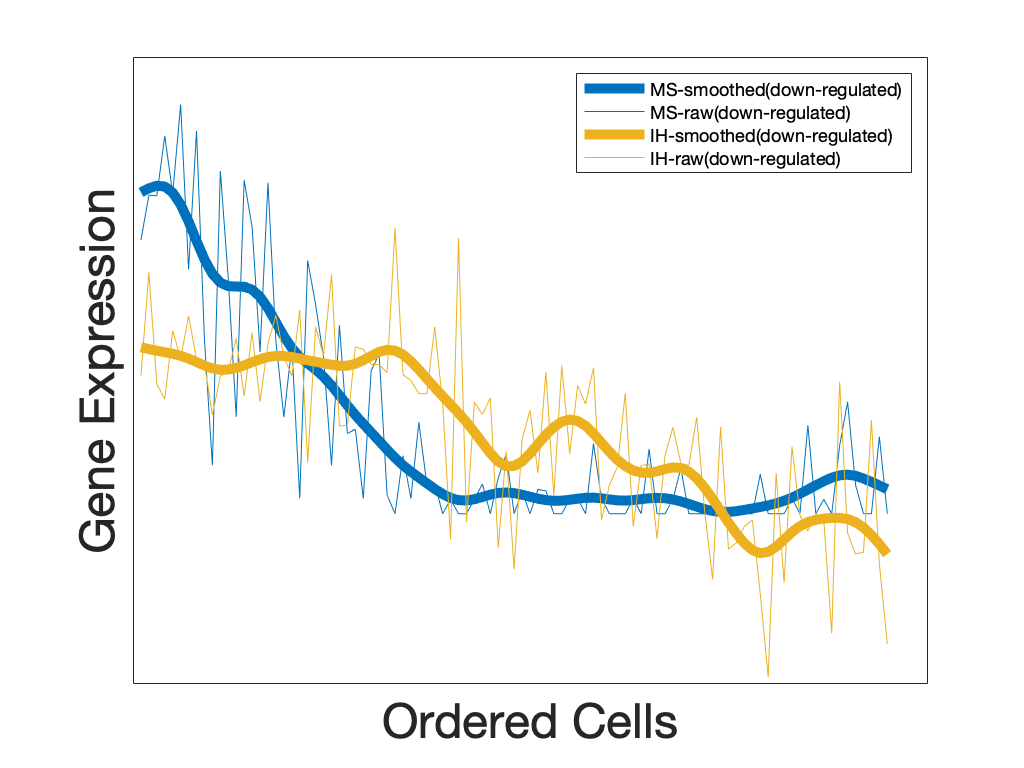

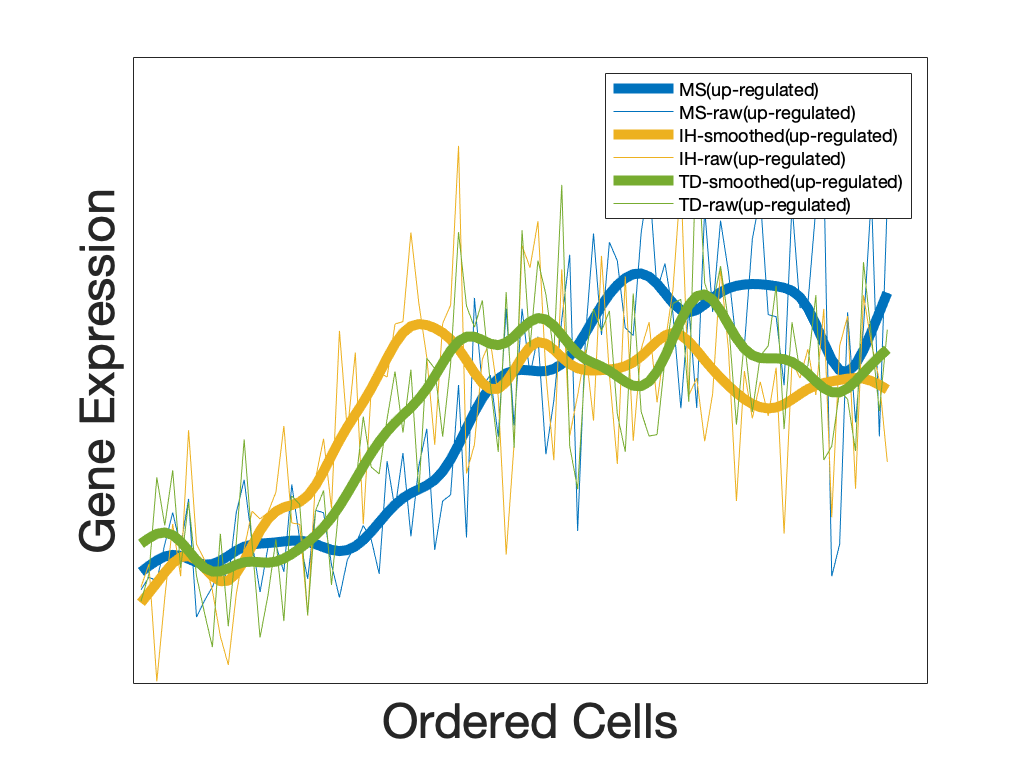

genes_analysis_out_indirect_2 = GeneAnalysis(3, 1, Output,par);

## Additonal figures of MuTrans Output

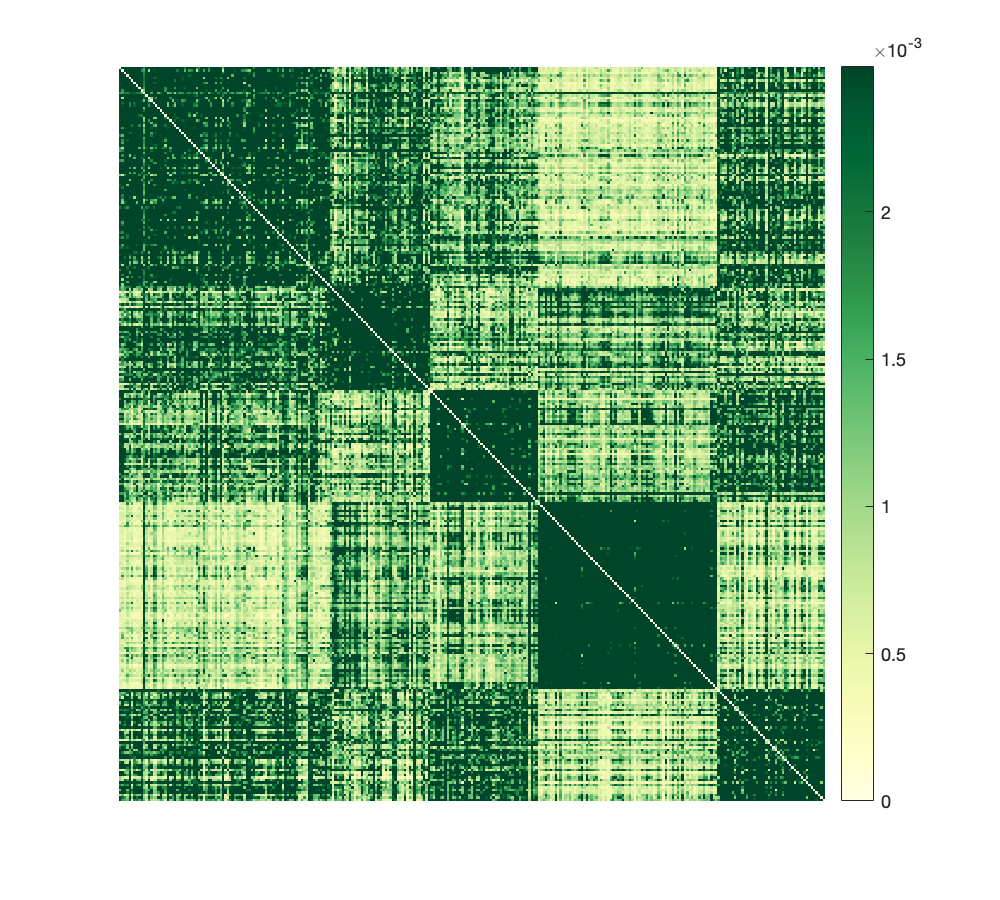

rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;



max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
colorbar;

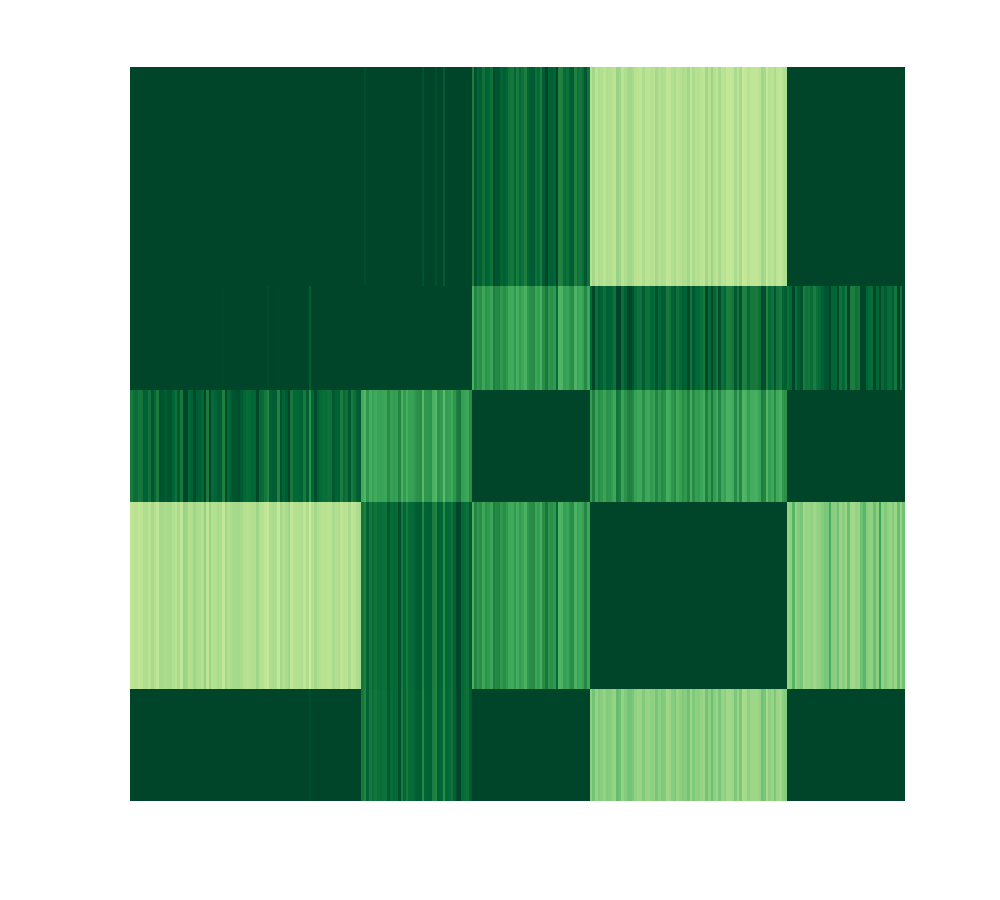



figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

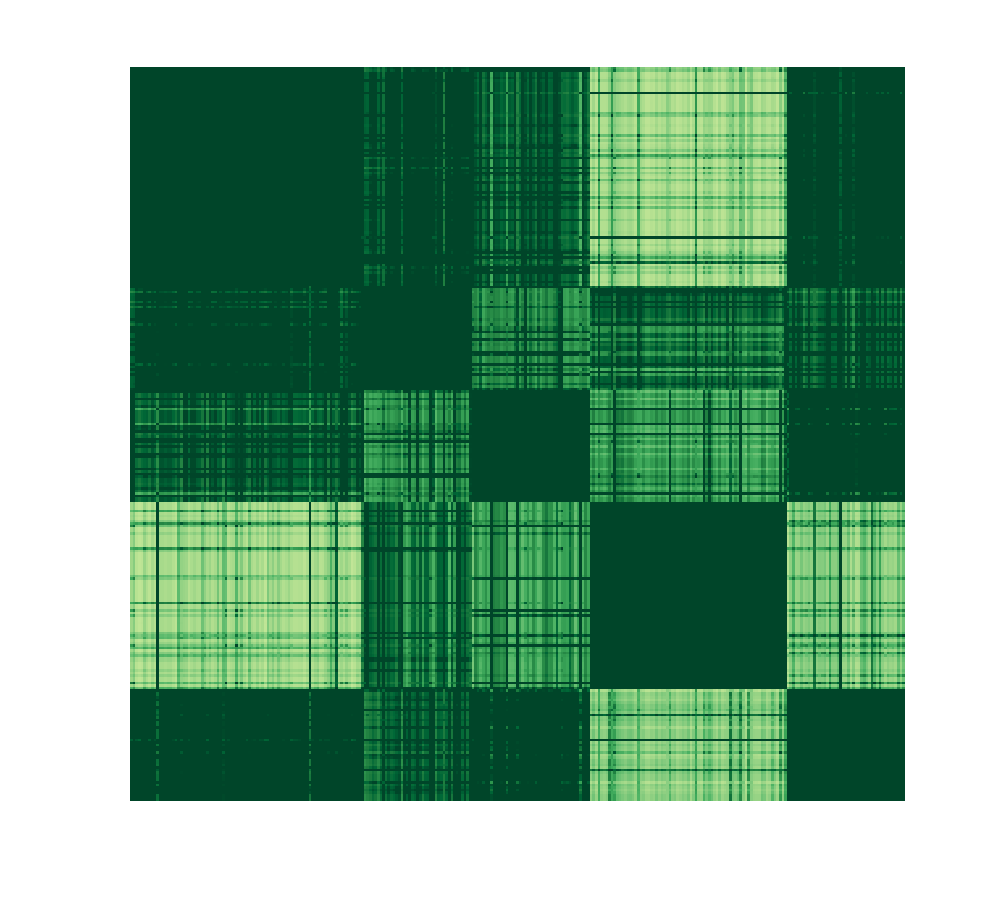

%colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

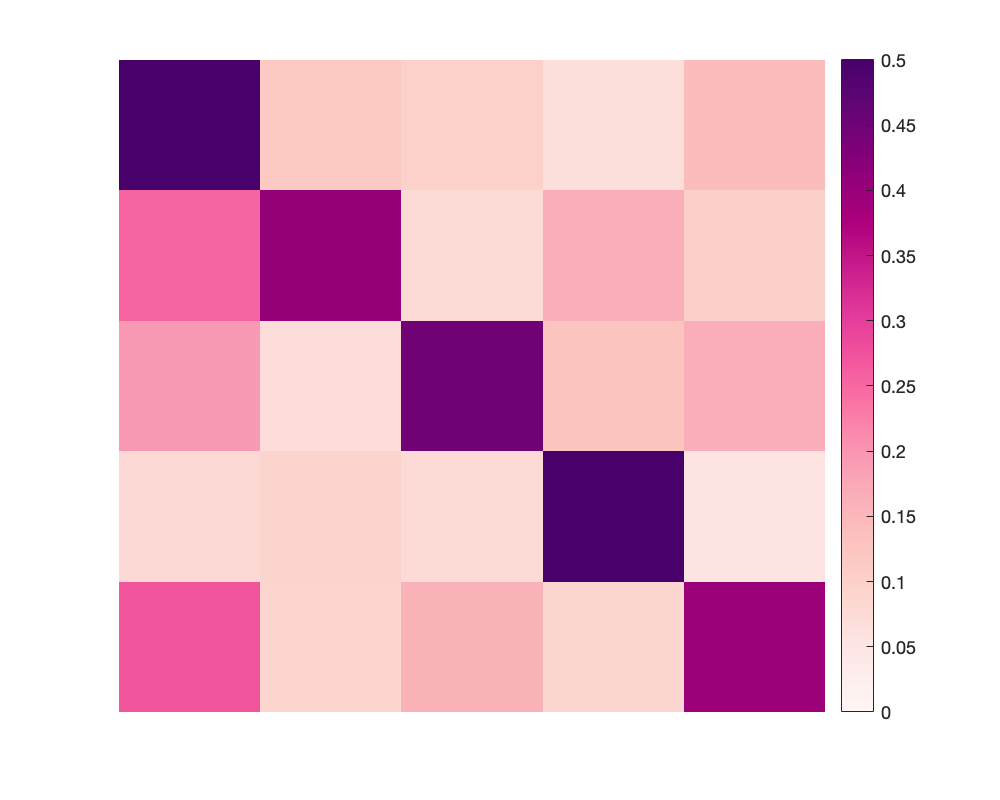



cmp = 'rdpu';
figure('rend','painters','pos',[10 10 500  400])
colormap(brewermap([],cmp))
imagesc(P_hat);
caxis([0 0.5])
axis off
set(gca,'xtick',[],'ytick',[]);
box off
colorbar;

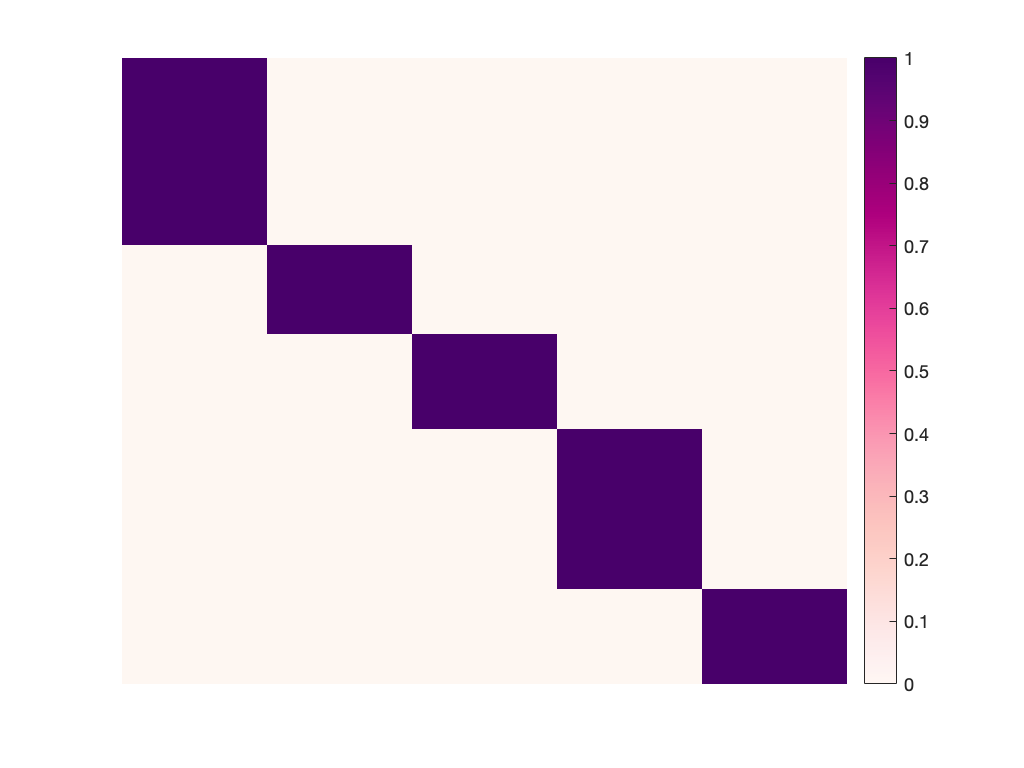


figure;
for id_cluster  = 1:k
member(:,id_cluster) = (class_order == id_cluster)';
end
colormap(brewermap([],cmp))
imagesc(member);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off

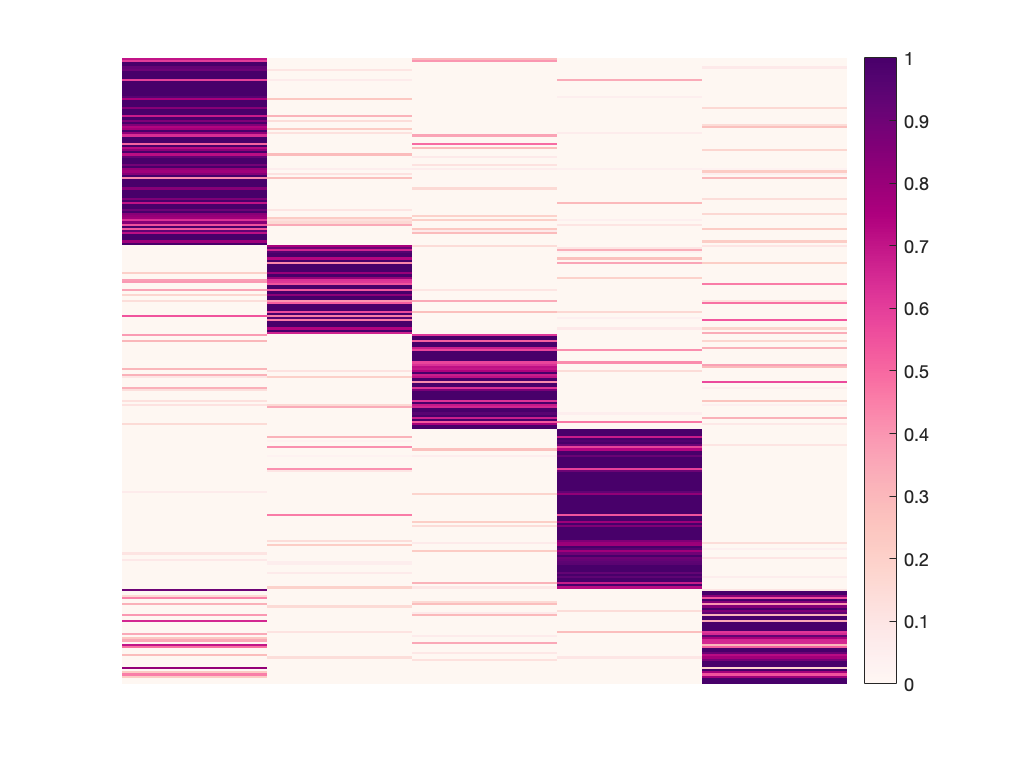


figure;
colormap(brewermap([],cmp))
imagesc(rho_class);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off